# OGLO PPC

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
generateCore();

addpath('fieldtrip');ft_defaults;

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

nwbPath = "data\";

nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));

disp("Toolbox setup done.");

Toolbox setup done.


## PART 1: Select data from OGLO spiking/LFP

% xsignal = z{10}{1}{4}; % PFC-AAAB-0825-SPK
% xsignal = z{10}{4}{4}; % PFC-AAAX-0825-SPK
% xsignal = z{8}{1}{3}; % MST-AAAB-0825-SPK
% xsignal = z{8}{4}{3}; % MST-AAAX-0825-SPK

xsignal = z{9}{1}{1}; % FEF-AAAB-0823-SPK
% xsignal = z{9}{4}{1}; % FEF-AAAX-0823-SPK
% xsignal = z{8}{1}{3}; % MST-AAAB-0825-SPK
% xsignal = z{8}{4}{3}; % MST-AAAX-0825-SPK

dataspike = jSignalArrayFT(xsignal, 'N');
% xsignal = x{13}{1}; % PFC-AAAB-0825-LFP
% xsignal = x{13}{4}; % PFC-AAAX-0825-LFP
% xsignal = x{14}{1}; % MST-AAAB-0825-LFP
% xsignal = x{13}{4}; % MST-AAAX-0825-LFP

% xsignal = x{10}{1}; % FEF-AAAB-0823-LFP
% xsignal = x{10}{4}; % FEF-AAAX-0823-LFP
xsignal = x{11}{1}; % MST-AAAB-0823-LFP
% xsignal = x{11}{4}; % MST-AAAX-0823-LFP

lfp = jSignalArrayFT(xsignal(:, 1:2:128, :), 'C');

## create a spike structure from the continuous structure

spike = ft_checkdata(dataspike, 'datatype', 'spike', 'feedback', 'yes');

the input is raw data with 109 channels and 219 trials
converting raw data into spike data


lfp = ft_checkdata(lfp, 'datatype', 'raw', 'feedback', 'yes');

the input is raw data with 64 channels and 219 trials


## PART 2: COMPUTE THE SPIKE TRIGGERED SPECTRA

cfg = []; 
cfg.foi = 10:100; 
cfg.taper = 'hann'; 
cfg.t_ftimwin = 5./cfg.foi;     
sts = ft_spiketriggeredspectrum_convol(cfg,lfp,spike);

the input is raw data with 64 channels and 219 trials
the input is spike data with 109 channels


Please wait...
Processing trial 34 from 219


## PART 3: COMPUTE MEASURE OF SPIKE-FIELD ASSOCIATION

## compute the measure of phase locking strength

nNeurons = length(spike.label);
ppc_all = NaN(nNeurons, length(sts.freq));
n_spikes = NaN(nNeurons, length(sts.freq));

for iNeuron = 1:nNeurons

    if length(sts.time{iNeuron})<3, continue,end
    
    % the code to compute for a single neuron
    cfg = []; 
    cfg.spikechannel = iNeuron; 
    cfg.method = 'ppc1'; 
    stat_ppc = ft_spiketriggeredspectrum_stat(cfg, sts); % this function takes only one input at a time
    
    % collect the data in some array for all neurons
    ppc_all(iNeuron,:) = mean(stat_ppc.ppc1, 1); % collect the ppc values across units
    n_spikes(iNeuron,:) = mean(stat_ppc.nspikes, 1); % collect the number of spikes for each neuron

end

the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 236 from 236

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 101 from 101

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 237 from 237

the call to "ft_spiketriggeredspectrum_stat" took 3 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 237 from 237

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 190 from 190

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 183 from 183

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 4 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 215 from 215

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 3 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 225 from 225

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 235 from 235

the call to "ft_spiketriggeredspectrum_stat" took 4 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 235 from 235

the call to "ft_spiketriggeredspectrum_stat" took 7 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 231 from 231

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 78 from 78

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 198 from 198

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 198 from 198

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 221 from 221

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 73 from 73

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 232 from 232

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 49 from 49

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 81 from 81

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 237 from 237

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 174 from 174

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 235 from 235

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 228 from 228

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 224 from 224

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 181 from 181

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 237 from 237

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 218 from 218

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 218 from 218

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 52 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 235 from 235

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 235 from 235

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 237 from 237

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 237 from 237

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 237 from 237

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 236 from 236

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 236 from 236

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 238 from 238

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 190 from 190

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 133 from 133

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 72 from 72

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 26 from 26

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 78 from 78

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 4 from 4

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 132 from 132

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 101 channels


Please wait...
Processing trial 8 from 8

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


## PART 4: VISUALIZE INDIVIDUAL NEURONS AND COMPUTE THE PHASE HISTOGRAM

% Note: this function still expects spike data to come in continuous
% format, as one structure. 
data_all = ft_appenddata([],lfp, dataspike); 

concatenating over the "chan" dimension
the call to "ft_selectdata" took 0 seconds
the call to "ft_appenddata" took 12 seconds


sta_all = []; 
nNeurons = 101;

for iNeuron = 1:nNeurons

    cfg = []; 
    cfg.spikechannel = dataspike.label{iNeuron};   
    cfg.channel = lfp.label{1};
    sta = ft_spiketriggeredaverage(cfg,data_all);
    sta_all(iNeuron,:) = sta.avg; 

end   

the input is raw data with 229 channels and 238 trials


the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (3 spikes)
processing trial 2 of 238 (4 spikes)
processing trial 3 of 238 (2 spikes)
processing trial 4 of 238 (2 spikes)
processing trial 5 of 238 (5 spikes)
processing trial 6 of 238 (1 spikes)
processing trial 7 of 238 (2 spikes)
processing trial 8 of 238 (3 spikes)
processing trial 9 of 238 (5 spikes)
processing trial 10 of 238 (10 spikes)
processing trial 11 of 238 (12 spikes)
processing trial 12 of 238 (9 spikes)
processing trial 13 of 238 (13 spikes)
processing trial 14 of 238 (6 spikes)
processing trial 15 of 238 (7 spikes)
processing trial 16 of 238 (10 spikes)
processing trial 17 of 238 (19 spikes)
processing trial 18 of 238 (13 spikes)
processing trial 19 of 238 (5 spikes)
processing trial 20 of 238 (9 spikes)
processing trial 21 of 238 (7 spikes)
processing tr

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (28 spikes)
processing trial 2 of 238 (97 spikes)
processing trial 3 of 238 (39 spikes)
processing trial 4 of 238 (25 spikes)
processing trial 5 of 238 (30 spikes)
processing trial 6 of 238 (15 spikes)
processing trial 7 of 238 (29 spikes)
processing trial 8 of 238 (33 spikes)
processing trial 9 of 238 (18 spikes)
processing trial 10 of 238 (24 spikes)
processing trial 11 of 238 (34 spikes)
processing trial 12 of 238 (25 spikes)
processing trial 13 of 238 (35 spikes)
processing trial 14 of 238 (25 spikes)
processing trial 15 of 238 (20 spikes)
processing trial 16 of 238 (33 spikes)
processing trial 17 of 238 (27 spikes)
processing trial 18 of 238 (24 spikes)
processing trial 19 of 238 (5 spikes)
processing trial 20 of 238 (7 spikes)
processing trial 21 of 238 (22 spikes)


the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (0 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (4 spikes)
processing trial 2 of 238 (5 spikes)
processing trial 3 of 238 (8 spikes)
processing trial 4 of 238 (3 spikes)
processing trial 5 of 238 (5 spikes)
processing trial 6 of 238 (1 spikes)
processing trial 7 of 238 (2 spikes)
processing trial 8 of 238 (9 spikes)
processing trial 9 of 238 (4 spikes)
processing trial 10 of 238 (6 spikes)
processing trial 11 of 238 (3 spikes)
processing trial 12 of 238 (7 spikes)
processing trial 13 of 238 (7 spikes)
processing trial 14 of 238 (4 spikes)
processing trial 15 of 238 (3 spikes)
processing trial 16 of 238 (8 spikes)
processing trial 17 of 238 (3 spikes)
processing trial 18 of 238 (5 spikes)
processing trial 19 of 238 (1 spikes)
processing trial 20 of 238 (2 spikes)
processing trial 21 of 238 (1 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (43 spikes)
processing trial 2 of 238 (43 spikes)
processing trial 3 of 238 (48 spikes)
processing trial 4 of 238 (45 spikes)
processing trial 5 of 238 (34 spikes)
processing trial 6 of 238 (32 spikes)
processing trial 7 of 238 (49 spikes)
processing trial 8 of 238 (28 spikes)
processing trial 9 of 238 (32 spikes)
processing trial 10 of 238 (30 spikes)
processing trial 11 of 238 (41 spikes)
processing trial 12 of 238 (40 spikes)
processing trial 13 of 238 (31 spikes)
processing trial 14 of 238 (38 spikes)
processing trial 15 of 238 (25 spikes)
processing trial 16 of 238 (39 spikes)
processing trial 17 of 238 (31 spikes)
processing trial 18 of 238 (34 spikes)
processing trial 19 of 238 (32 spikes)
processing trial 20 of 238 (41 spikes)
processing trial 21 of 238 (52 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (0 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (1 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (1 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (2 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (1 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (0 spikes)
processing trial 2 of 238 (2 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (1 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (1 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (68 spikes)
processing trial 2 of 238 (94 spikes)
processing trial 3 of 238 (104 spikes)
processing trial 4 of 238 (45 spikes)
processing trial 5 of 238 (84 spikes)
processing trial 6 of 238 (92 spikes)
processing trial 7 of 238 (83 spikes)
processing trial 8 of 238 (58 spikes)
processing trial 9 of 238 (81 spikes)
processing trial 10 of 238 (81 spikes)
processing trial 11 of 238 (81 spikes)
processing trial 12 of 238 (76 spikes)
processing trial 13 of 238 (91 spikes)
processing trial 14 of 238 (97 spikes)
processing trial 15 of 238 (76 spikes)
processing trial 16 of 238 (73 spikes)
processing trial 17 of 238 (74 spikes)
processing trial 18 of 238 (86 spikes)
processing trial 19 of 238 (103 spikes)
processing trial 20 of 238 (79 spikes)
processing trial 21 of 238 (93 spik

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (7 spikes)
processing trial 2 of 238 (4 spikes)
processing trial 3 of 238 (7 spikes)
processing trial 4 of 238 (5 spikes)
processing trial 5 of 238 (10 spikes)
processing trial 6 of 238 (1 spikes)
processing trial 7 of 238 (1 spikes)
processing trial 8 of 238 (1 spikes)
processing trial 9 of 238 (1 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (1 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (1 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (1 spikes)
processing trial 2

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (74 spikes)
processing trial 2 of 238 (78 spikes)
processing trial 3 of 238 (73 spikes)
processing trial 4 of 238 (82 spikes)
processing trial 5 of 238 (69 spikes)
processing trial 6 of 238 (77 spikes)
processing trial 7 of 238 (67 spikes)
processing trial 8 of 238 (85 spikes)
processing trial 9 of 238 (70 spikes)
processing trial 10 of 238 (72 spikes)
processing trial 11 of 238 (72 spikes)
processing trial 12 of 238 (84 spikes)
processing trial 13 of 238 (70 spikes)
processing trial 14 of 238 (72 spikes)
processing trial 15 of 238 (67 spikes)
processing trial 16 of 238 (66 spikes)
processing trial 17 of 238 (77 spikes)
processing trial 18 of 238 (80 spikes)
processing trial 19 of 238 (76 spikes)
processing trial 20 of 238 (82 spikes)
processing trial 21 of 238 (88 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (34 spikes)
processing trial 2 of 238 (11 spikes)
processing trial 3 of 238 (21 spikes)
processing trial 4 of 238 (10 spikes)
processing trial 5 of 238 (26 spikes)
processing trial 6 of 238 (4 spikes)
processing trial 7 of 238 (12 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (16 spikes)
processing trial 10 of 238 (23 spikes)
processing trial 11 of 238 (17 spikes)
processing trial 12 of 238 (15 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (19 spikes)
processing trial 15 of 238 (10 spikes)
processing trial 16 of 238 (9 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (3 spikes)
processing trial 19 of 238 (11 spikes)
processing trial 20 of 238 (9 spikes)
processing trial 21 of 238 (0 spikes)
proces

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (65 spikes)
processing trial 2 of 238 (32 spikes)
processing trial 3 of 238 (38 spikes)
processing trial 4 of 238 (49 spikes)
processing trial 5 of 238 (25 spikes)
processing trial 6 of 238 (30 spikes)
processing trial 7 of 238 (40 spikes)
processing trial 8 of 238 (34 spikes)
processing trial 9 of 238 (30 spikes)
processing trial 10 of 238 (21 spikes)
processing trial 11 of 238 (31 spikes)
processing trial 12 of 238 (29 spikes)
processing trial 13 of 238 (27 spikes)
processing trial 14 of 238 (22 spikes)
processing trial 15 of 238 (25 spikes)
processing trial 16 of 238 (30 spikes)
processing trial 17 of 238 (36 spikes)
processing trial 18 of 238 (12 spikes)
processing trial 19 of 238 (18 spikes)
processing trial 20 of 238 (20 spikes)
processing trial 21 of 238 (32 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (4 spikes)
processing trial 2 of 238 (6 spikes)
processing trial 3 of 238 (10 spikes)
processing trial 4 of 238 (7 spikes)
processing trial 5 of 238 (3 spikes)
processing trial 6 of 238 (3 spikes)
processing trial 7 of 238 (6 spikes)
processing trial 8 of 238 (2 spikes)
processing trial 9 of 238 (7 spikes)
processing trial 10 of 238 (4 spikes)
processing trial 11 of 238 (8 spikes)
processing trial 12 of 238 (11 spikes)
processing trial 13 of 238 (12 spikes)
processing trial 14 of 238 (8 spikes)
processing trial 15 of 238 (15 spikes)
processing trial 16 of 238 (7 spikes)
processing trial 17 of 238 (12 spikes)
processing trial 18 of 238 (5 spikes)
processing trial 19 of 238 (11 spikes)
processing trial 20 of 238 (11 spikes)
processing trial 21 of 238 (12 spikes)
processing 

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (42 spikes)
processing trial 2 of 238 (20 spikes)
processing trial 3 of 238 (63 spikes)
processing trial 4 of 238 (28 spikes)
processing trial 5 of 238 (23 spikes)
processing trial 6 of 238 (36 spikes)
processing trial 7 of 238 (60 spikes)
processing trial 8 of 238 (27 spikes)
processing trial 9 of 238 (32 spikes)
processing trial 10 of 238 (30 spikes)
processing trial 11 of 238 (13 spikes)
processing trial 12 of 238 (23 spikes)
processing trial 13 of 238 (15 spikes)
processing trial 14 of 238 (22 spikes)
processing trial 15 of 238 (16 spikes)
processing trial 16 of 238 (11 spikes)
processing trial 17 of 238 (35 spikes)
processing trial 18 of 238 (20 spikes)
processing trial 19 of 238 (31 spikes)
processing trial 20 of 238 (20 spikes)
processing trial 21 of 238 (43 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (31 spikes)
processing trial 2 of 238 (19 spikes)
processing trial 3 of 238 (53 spikes)
processing trial 4 of 238 (15 spikes)
processing trial 5 of 238 (22 spikes)
processing trial 6 of 238 (14 spikes)
processing trial 7 of 238 (49 spikes)
processing trial 8 of 238 (26 spikes)
processing trial 9 of 238 (20 spikes)
processing trial 10 of 238 (27 spikes)
processing trial 11 of 238 (9 spikes)
processing trial 12 of 238 (23 spikes)
processing trial 13 of 238 (15 spikes)
processing trial 14 of 238 (17 spikes)
processing trial 15 of 238 (9 spikes)
processing trial 16 of 238 (10 spikes)
processing trial 17 of 238 (28 spikes)
processing trial 18 of 238 (18 spikes)
processing trial 19 of 238 (16 spikes)
processing trial 20 of 238 (11 spikes)
processing trial 21 of 238 (19 spikes)


the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (44 spikes)
processing trial 2 of 238 (19 spikes)
processing trial 3 of 238 (65 spikes)
processing trial 4 of 238 (28 spikes)
processing trial 5 of 238 (23 spikes)
processing trial 6 of 238 (37 spikes)
processing trial 7 of 238 (58 spikes)
processing trial 8 of 238 (29 spikes)
processing trial 9 of 238 (33 spikes)
processing trial 10 of 238 (30 spikes)
processing trial 11 of 238 (13 spikes)
processing trial 12 of 238 (23 spikes)
processing trial 13 of 238 (15 spikes)
processing trial 14 of 238 (21 spikes)
processing trial 15 of 238 (16 spikes)
processing trial 16 of 238 (12 spikes)
processing trial 17 of 238 (36 spikes)
processing trial 18 of 238 (20 spikes)
processing trial 19 of 238 (32 spikes)
processing trial 20 of 238 (20 spikes)
processing trial 21 of 238 (44 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (83 spikes)
processing trial 2 of 238 (93 spikes)
processing trial 3 of 238 (83 spikes)
processing trial 4 of 238 (96 spikes)
processing trial 5 of 238 (72 spikes)
processing trial 6 of 238 (85 spikes)
processing trial 7 of 238 (68 spikes)
processing trial 8 of 238 (88 spikes)
processing trial 9 of 238 (85 spikes)
processing trial 10 of 238 (87 spikes)
processing trial 11 of 238 (85 spikes)
processing trial 12 of 238 (84 spikes)
processing trial 13 of 238 (82 spikes)
processing trial 14 of 238 (93 spikes)
processing trial 15 of 238 (87 spikes)
processing trial 16 of 238 (100 spikes)
processing trial 17 of 238 (90 spikes)
processing trial 18 of 238 (95 spikes)
processing trial 19 of 238 (76 spikes)
processing trial 20 of 238 (79 spikes)
processing trial 21 of 238 (86 spike

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (4 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (1 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (1 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (1 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (31 spikes)
processing trial 18 of 238 (9 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 2

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (1 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (1 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (30 spikes)
processing trial 18 of 238 (9 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 2

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (4 spikes)
processing trial 2 of 238 (6 spikes)
processing trial 3 of 238 (1 spikes)
processing trial 4 of 238 (1 spikes)
processing trial 5 of 238 (11 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (3 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (6 spikes)
processing trial 12 of 238 (2 spikes)
processing trial 13 of 238 (6 spikes)
processing trial 14 of 238 (2 spikes)
processing trial 15 of 238 (3 spikes)
processing trial 16 of 238 (2 spikes)
processing trial 17 of 238 (8 spikes)
processing trial 18 of 238 (4 spikes)
processing trial 19 of 238 (2 spikes)
processing trial 20 of 238 (4 spikes)
processing trial 21 of 238 (4 spikes)
processing trial 2

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (1 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (1 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (1 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (1 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (8 spikes)
processing trial 2 of 238 (6 spikes)
processing trial 3 of 238 (9 spikes)
processing trial 4 of 238 (6 spikes)
processing trial 5 of 238 (4 spikes)
processing trial 6 of 238 (11 spikes)
processing trial 7 of 238 (6 spikes)
processing trial 8 of 238 (2 spikes)
processing trial 9 of 238 (5 spikes)
processing trial 10 of 238 (6 spikes)
processing trial 11 of 238 (3 spikes)
processing trial 12 of 238 (3 spikes)
processing trial 13 of 238 (5 spikes)
processing trial 14 of 238 (1 spikes)
processing trial 15 of 238 (6 spikes)
processing trial 16 of 238 (1 spikes)
processing trial 17 of 238 (3 spikes)
processing trial 18 of 238 (1 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (6 spikes)
processing trial 21 of 238 (4 spikes)
processing trial 2

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (0 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (1 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (15 spikes)
processing trial 2 of 238 (6 spikes)
processing trial 3 of 238 (7 spikes)
processing trial 4 of 238 (6 spikes)
processing trial 5 of 238 (8 spikes)
processing trial 6 of 238 (20 spikes)
processing trial 7 of 238 (22 spikes)
processing trial 8 of 238 (7 spikes)
processing trial 9 of 238 (7 spikes)
processing trial 10 of 238 (12 spikes)
processing trial 11 of 238 (7 spikes)
processing trial 12 of 238 (5 spikes)
processing trial 13 of 238 (7 spikes)
processing trial 14 of 238 (6 spikes)
processing trial 15 of 238 (2 spikes)
processing trial 16 of 238 (2 spikes)
processing trial 17 of 238 (5 spikes)
processing trial 18 of 238 (4 spikes)
processing trial 19 of 238 (3 spikes)
processing trial 20 of 238 (6 spikes)
processing trial 21 of 238 (3 spikes)
processing tria

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (28 spikes)
processing trial 2 of 238 (19 spikes)
processing trial 3 of 238 (14 spikes)
processing trial 4 of 238 (14 spikes)
processing trial 5 of 238 (34 spikes)
processing trial 6 of 238 (59 spikes)
processing trial 7 of 238 (44 spikes)
processing trial 8 of 238 (25 spikes)
processing trial 9 of 238 (33 spikes)
processing trial 10 of 238 (24 spikes)
processing trial 11 of 238 (26 spikes)
processing trial 12 of 238 (5 spikes)
processing trial 13 of 238 (11 spikes)
processing trial 14 of 238 (3 spikes)
processing trial 15 of 238 (5 spikes)
processing trial 16 of 238 (5 spikes)
processing trial 17 of 238 (2 spikes)
processing trial 18 of 238 (4 spikes)
processing trial 19 of 238 (3 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (1 spikes)
process

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (3 spikes)
processing trial 2 of 238 (2 spikes)
processing trial 3 of 238 (1 spikes)
processing trial 4 of 238 (2 spikes)
processing trial 5 of 238 (1 spikes)
processing trial 6 of 238 (3 spikes)
processing trial 7 of 238 (7 spikes)
processing trial 8 of 238 (5 spikes)
processing trial 9 of 238 (7 spikes)
processing trial 10 of 238 (5 spikes)
processing trial 11 of 238 (1 spikes)
processing trial 12 of 238 (2 spikes)
processing trial 13 of 238 (4 spikes)
processing trial 14 of 238 (6 spikes)
processing trial 15 of 238 (13 spikes)
processing trial 16 of 238 (6 spikes)
processing trial 17 of 238 (17 spikes)
processing trial 18 of 238 (11 spikes)
processing trial 19 of 238 (8 spikes)
processing trial 20 of 238 (10 spikes)
processing trial 21 of 238 (11 spikes)
processing tri

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (30 spikes)
processing trial 2 of 238 (8 spikes)
processing trial 3 of 238 (6 spikes)
processing trial 4 of 238 (321 spikes)
processing trial 5 of 238 (9 spikes)
processing trial 6 of 238 (17 spikes)
processing trial 7 of 238 (47 spikes)
processing trial 8 of 238 (7 spikes)
processing trial 9 of 238 (15 spikes)
processing trial 10 of 238 (7 spikes)
processing trial 11 of 238 (15 spikes)
processing trial 12 of 238 (10 spikes)
processing trial 13 of 238 (4 spikes)
processing trial 14 of 238 (10 spikes)
processing trial 15 of 238 (5 spikes)
processing trial 16 of 238 (10 spikes)
processing trial 17 of 238 (7 spikes)
processing trial 18 of 238 (2 spikes)
processing trial 19 of 238 (1 spikes)
processing trial 20 of 238 (2 spikes)
processing trial 21 of 238 (1 spikes)
processin

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (8 spikes)
processing trial 2 of 238 (18 spikes)
processing trial 3 of 238 (11 spikes)
processing trial 4 of 238 (7 spikes)
processing trial 5 of 238 (16 spikes)
processing trial 6 of 238 (14 spikes)
processing trial 7 of 238 (11 spikes)
processing trial 8 of 238 (11 spikes)
processing trial 9 of 238 (2 spikes)
processing trial 10 of 238 (3 spikes)
processing trial 11 of 238 (7 spikes)
processing trial 12 of 238 (5 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (2 spikes)
processing trial 15 of 238 (2 spikes)
processing trial 16 of 238 (2 spikes)
processing trial 17 of 238 (2 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (5 spikes)
processing trial 20 of 238 (12 spikes)
processing trial 21 of 238 (5 spikes)
processing t

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (3 spikes)
processing trial 2 of 238 (7 spikes)
processing trial 3 of 238 (4 spikes)
processing trial 4 of 238 (1 spikes)
processing trial 5 of 238 (4 spikes)
processing trial 6 of 238 (3 spikes)
processing trial 7 of 238 (4 spikes)
processing trial 8 of 238 (2 spikes)
processing trial 9 of 238 (4 spikes)
processing trial 10 of 238 (3 spikes)
processing trial 11 of 238 (1 spikes)
processing trial 12 of 238 (3 spikes)
processing trial 13 of 238 (1 spikes)
processing trial 14 of 238 (7 spikes)
processing trial 15 of 238 (10 spikes)
processing trial 16 of 238 (6 spikes)
processing trial 17 of 238 (4 spikes)
processing trial 18 of 238 (7 spikes)
processing trial 19 of 238 (1 spikes)
processing trial 20 of 238 (7 spikes)
processing trial 21 of 238 (3 spikes)
processing trial 2

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (0 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (4 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (2 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (1 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (5 spikes)
processing trial 2 of 238 (1 spikes)
processing trial 3 of 238 (6 spikes)
processing trial 4 of 238 (6 spikes)
processing trial 5 of 238 (7 spikes)
processing trial 6 of 238 (8 spikes)
processing trial 7 of 238 (6 spikes)
processing trial 8 of 238 (3 spikes)
processing trial 9 of 238 (1 spikes)
processing trial 10 of 238 (4 spikes)
processing trial 11 of 238 (4 spikes)
processing trial 12 of 238 (8 spikes)
processing trial 13 of 238 (3 spikes)
processing trial 14 of 238 (2 spikes)
processing trial 15 of 238 (5 spikes)
processing trial 16 of 238 (7 spikes)
processing trial 17 of 238 (2 spikes)
processing trial 18 of 238 (10 spikes)
processing trial 19 of 238 (4 spikes)
processing trial 20 of 238 (6 spikes)
processing trial 21 of 238 (2 spikes)
processing trial 2

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (3 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (1 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (1 spikes)
processing trial 7 of 238 (3 spikes)
processing trial 8 of 238 (1 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (3 spikes)
processing trial 11 of 238 (1 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (4 spikes)
processing trial 14 of 238 (1 spikes)
processing trial 15 of 238 (2 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (2 spikes)
processing trial 18 of 238 (4 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (3 spikes)
processing trial 21 of 238 (1 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (4 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (3 spikes)
processing trial 4 of 238 (3 spikes)
processing trial 5 of 238 (1 spikes)
processing trial 6 of 238 (6 spikes)
processing trial 7 of 238 (5 spikes)
processing trial 8 of 238 (4 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (4 spikes)
processing trial 11 of 238 (2 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (6 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (4 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (3 spikes)
processing trial 19 of 238 (3 spikes)
processing trial 20 of 238 (3 spikes)
processing trial 21 of 238 (1 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (1099 spikes)
processing trial 2 of 238 (827 spikes)
processing trial 3 of 238 (9 spikes)
processing trial 4 of 238 (1146 spikes)
processing trial 5 of 238 (301 spikes)
processing trial 6 of 238 (220 spikes)
processing trial 7 of 238 (129 spikes)
processing trial 8 of 238 (26 spikes)
processing trial 9 of 238 (1277 spikes)
processing trial 10 of 238 (43 spikes)
processing trial 11 of 238 (118 spikes)
processing trial 12 of 238 (237 spikes)
processing trial 13 of 238 (389 spikes)
processing trial 14 of 238 (433 spikes)
processing trial 15 of 238 (167 spikes)
processing trial 16 of 238 (278 spikes)
processing trial 17 of 238 (1105 spikes)
processing trial 18 of 238 (17 spikes)
processing trial 19 of 238 (263 spikes)
processing trial 20 of 238 (40 spikes)
processing trial 21

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (28 spikes)
processing trial 2 of 238 (16 spikes)
processing trial 3 of 238 (24 spikes)
processing trial 4 of 238 (33 spikes)
processing trial 5 of 238 (12 spikes)
processing trial 6 of 238 (22 spikes)
processing trial 7 of 238 (9 spikes)
processing trial 8 of 238 (16 spikes)
processing trial 9 of 238 (24 spikes)
processing trial 10 of 238 (15 spikes)
processing trial 11 of 238 (33 spikes)
processing trial 12 of 238 (12 spikes)
processing trial 13 of 238 (55 spikes)
processing trial 14 of 238 (16 spikes)
processing trial 15 of 238 (9 spikes)
processing trial 16 of 238 (7 spikes)
processing trial 17 of 238 (15 spikes)
processing trial 18 of 238 (36 spikes)
processing trial 19 of 238 (4 spikes)
processing trial 20 of 238 (26 spikes)
processing trial 21 of 238 (6 spikes)
pro

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (15 spikes)
processing trial 2 of 238 (17 spikes)
processing trial 3 of 238 (20 spikes)
processing trial 4 of 238 (11 spikes)
processing trial 5 of 238 (10 spikes)
processing trial 6 of 238 (11 spikes)
processing trial 7 of 238 (16 spikes)
processing trial 8 of 238 (12 spikes)
processing trial 9 of 238 (17 spikes)
processing trial 10 of 238 (33 spikes)
processing trial 11 of 238 (44 spikes)
processing trial 12 of 238 (38 spikes)
processing trial 13 of 238 (36 spikes)
processing trial 14 of 238 (48 spikes)
processing trial 15 of 238 (42 spikes)
processing trial 16 of 238 (35 spikes)
processing trial 17 of 238 (34 spikes)
processing trial 18 of 238 (39 spikes)
processing trial 19 of 238 (17 spikes)
processing trial 20 of 238 (57 spikes)
processing trial 21 of 238 (34 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (40 spikes)
processing trial 2 of 238 (20 spikes)
processing trial 3 of 238 (26 spikes)
processing trial 4 of 238 (29 spikes)
processing trial 5 of 238 (31 spikes)
processing trial 6 of 238 (26 spikes)
processing trial 7 of 238 (35 spikes)
processing trial 8 of 238 (30 spikes)
processing trial 9 of 238 (28 spikes)
processing trial 10 of 238 (16 spikes)
processing trial 11 of 238 (32 spikes)
processing trial 12 of 238 (12 spikes)
processing trial 13 of 238 (14 spikes)
processing trial 14 of 238 (80 spikes)
processing trial 15 of 238 (27 spikes)
processing trial 16 of 238 (24 spikes)
processing trial 17 of 238 (40 spikes)
processing trial 18 of 238 (9 spikes)
processing trial 19 of 238 (8 spikes)
processing trial 20 of 238 (5 spikes)
processing trial 21 of 238 (14 spikes)
p

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (9 spikes)
processing trial 2 of 238 (8 spikes)
processing trial 3 of 238 (9 spikes)
processing trial 4 of 238 (10 spikes)
processing trial 5 of 238 (6 spikes)
processing trial 6 of 238 (15 spikes)
processing trial 7 of 238 (17 spikes)
processing trial 8 of 238 (11 spikes)
processing trial 9 of 238 (11 spikes)
processing trial 10 of 238 (10 spikes)
processing trial 11 of 238 (11 spikes)
processing trial 12 of 238 (11 spikes)
processing trial 13 of 238 (8 spikes)
processing trial 14 of 238 (12 spikes)
processing trial 15 of 238 (9 spikes)
processing trial 16 of 238 (8 spikes)
processing trial 17 of 238 (10 spikes)
processing trial 18 of 238 (11 spikes)
processing trial 19 of 238 (13 spikes)
processing trial 20 of 238 (11 spikes)
processing trial 21 of 238 (9 spikes)
proces

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (4 spikes)
processing trial 2 of 238 (2 spikes)
processing trial 3 of 238 (6 spikes)
processing trial 4 of 238 (2 spikes)
processing trial 5 of 238 (5 spikes)
processing trial 6 of 238 (4 spikes)
processing trial 7 of 238 (8 spikes)
processing trial 8 of 238 (7 spikes)
processing trial 9 of 238 (5 spikes)
processing trial 10 of 238 (12 spikes)
processing trial 11 of 238 (7 spikes)
processing trial 12 of 238 (13 spikes)
processing trial 13 of 238 (2 spikes)
processing trial 14 of 238 (8 spikes)
processing trial 15 of 238 (21 spikes)
processing trial 16 of 238 (26 spikes)
processing trial 17 of 238 (16 spikes)
processing trial 18 of 238 (4 spikes)
processing trial 19 of 238 (15 spikes)
processing trial 20 of 238 (14 spikes)
processing trial 21 of 238 (28 spikes)
processing 

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (54 spikes)
processing trial 2 of 238 (48 spikes)
processing trial 3 of 238 (58 spikes)
processing trial 4 of 238 (58 spikes)
processing trial 5 of 238 (61 spikes)
processing trial 6 of 238 (70 spikes)
processing trial 7 of 238 (69 spikes)
processing trial 8 of 238 (56 spikes)
processing trial 9 of 238 (57 spikes)
processing trial 10 of 238 (64 spikes)
processing trial 11 of 238 (49 spikes)
processing trial 12 of 238 (54 spikes)
processing trial 13 of 238 (63 spikes)
processing trial 14 of 238 (61 spikes)
processing trial 15 of 238 (53 spikes)
processing trial 16 of 238 (52 spikes)
processing trial 17 of 238 (63 spikes)
processing trial 18 of 238 (50 spikes)
processing trial 19 of 238 (52 spikes)
processing trial 20 of 238 (46 spikes)
processing trial 21 of 238 (55 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (54 spikes)
processing trial 2 of 238 (53 spikes)
processing trial 3 of 238 (35 spikes)
processing trial 4 of 238 (34 spikes)
processing trial 5 of 238 (36 spikes)
processing trial 6 of 238 (36 spikes)
processing trial 7 of 238 (55 spikes)
processing trial 8 of 238 (38 spikes)
processing trial 9 of 238 (28 spikes)
processing trial 10 of 238 (39 spikes)
processing trial 11 of 238 (35 spikes)
processing trial 12 of 238 (36 spikes)
processing trial 13 of 238 (41 spikes)
processing trial 14 of 238 (37 spikes)
processing trial 15 of 238 (45 spikes)
processing trial 16 of 238 (37 spikes)
processing trial 17 of 238 (35 spikes)
processing trial 18 of 238 (44 spikes)
processing trial 19 of 238 (29 spikes)
processing trial 20 of 238 (34 spikes)
processing trial 21 of 238 (41 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (53 spikes)
processing trial 2 of 238 (57 spikes)
processing trial 3 of 238 (55 spikes)
processing trial 4 of 238 (45 spikes)
processing trial 5 of 238 (56 spikes)
processing trial 6 of 238 (49 spikes)
processing trial 7 of 238 (62 spikes)
processing trial 8 of 238 (52 spikes)
processing trial 9 of 238 (61 spikes)
processing trial 10 of 238 (53 spikes)
processing trial 11 of 238 (47 spikes)
processing trial 12 of 238 (52 spikes)
processing trial 13 of 238 (59 spikes)
processing trial 14 of 238 (40 spikes)
processing trial 15 of 238 (45 spikes)
processing trial 16 of 238 (50 spikes)
processing trial 17 of 238 (58 spikes)
processing trial 18 of 238 (47 spikes)
processing trial 19 of 238 (47 spikes)
processing trial 20 of 238 (42 spikes)
processing trial 21 of 238 (43 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (59 spikes)
processing trial 2 of 238 (47 spikes)
processing trial 3 of 238 (58 spikes)
processing trial 4 of 238 (46 spikes)
processing trial 5 of 238 (52 spikes)
processing trial 6 of 238 (49 spikes)
processing trial 7 of 238 (45 spikes)
processing trial 8 of 238 (49 spikes)
processing trial 9 of 238 (59 spikes)
processing trial 10 of 238 (39 spikes)
processing trial 11 of 238 (41 spikes)
processing trial 12 of 238 (51 spikes)
processing trial 13 of 238 (55 spikes)
processing trial 14 of 238 (53 spikes)
processing trial 15 of 238 (57 spikes)
processing trial 16 of 238 (41 spikes)
processing trial 17 of 238 (56 spikes)
processing trial 18 of 238 (52 spikes)
processing trial 19 of 238 (53 spikes)
processing trial 20 of 238 (48 spikes)
processing trial 21 of 238 (51 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (41 spikes)
processing trial 2 of 238 (52 spikes)
processing trial 3 of 238 (40 spikes)
processing trial 4 of 238 (30 spikes)
processing trial 5 of 238 (43 spikes)
processing trial 6 of 238 (37 spikes)
processing trial 7 of 238 (37 spikes)
processing trial 8 of 238 (37 spikes)
processing trial 9 of 238 (33 spikes)
processing trial 10 of 238 (53 spikes)
processing trial 11 of 238 (37 spikes)
processing trial 12 of 238 (45 spikes)
processing trial 13 of 238 (34 spikes)
processing trial 14 of 238 (41 spikes)
processing trial 15 of 238 (26 spikes)
processing trial 16 of 238 (30 spikes)
processing trial 17 of 238 (39 spikes)
processing trial 18 of 238 (31 spikes)
processing trial 19 of 238 (30 spikes)
processing trial 20 of 238 (35 spikes)
processing trial 21 of 238 (33 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (48 spikes)
processing trial 2 of 238 (57 spikes)
processing trial 3 of 238 (48 spikes)
processing trial 4 of 238 (49 spikes)
processing trial 5 of 238 (54 spikes)
processing trial 6 of 238 (46 spikes)
processing trial 7 of 238 (48 spikes)
processing trial 8 of 238 (51 spikes)
processing trial 9 of 238 (45 spikes)
processing trial 10 of 238 (49 spikes)
processing trial 11 of 238 (46 spikes)
processing trial 12 of 238 (53 spikes)
processing trial 13 of 238 (49 spikes)
processing trial 14 of 238 (48 spikes)
processing trial 15 of 238 (55 spikes)
processing trial 16 of 238 (48 spikes)
processing trial 17 of 238 (47 spikes)
processing trial 18 of 238 (59 spikes)
processing trial 19 of 238 (32 spikes)
processing trial 20 of 238 (60 spikes)
processing trial 21 of 238 (50 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (48 spikes)
processing trial 2 of 238 (52 spikes)
processing trial 3 of 238 (51 spikes)
processing trial 4 of 238 (56 spikes)
processing trial 5 of 238 (61 spikes)
processing trial 6 of 238 (47 spikes)
processing trial 7 of 238 (38 spikes)
processing trial 8 of 238 (42 spikes)
processing trial 9 of 238 (50 spikes)
processing trial 10 of 238 (54 spikes)
processing trial 11 of 238 (35 spikes)
processing trial 12 of 238 (57 spikes)
processing trial 13 of 238 (54 spikes)
processing trial 14 of 238 (50 spikes)
processing trial 15 of 238 (54 spikes)
processing trial 16 of 238 (60 spikes)
processing trial 17 of 238 (59 spikes)
processing trial 18 of 238 (54 spikes)
processing trial 19 of 238 (44 spikes)
processing trial 20 of 238 (47 spikes)
processing trial 21 of 238 (48 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (77 spikes)
processing trial 2 of 238 (56 spikes)
processing trial 3 of 238 (58 spikes)
processing trial 4 of 238 (63 spikes)
processing trial 5 of 238 (57 spikes)
processing trial 6 of 238 (62 spikes)
processing trial 7 of 238 (52 spikes)
processing trial 8 of 238 (55 spikes)
processing trial 9 of 238 (52 spikes)
processing trial 10 of 238 (65 spikes)
processing trial 11 of 238 (64 spikes)
processing trial 12 of 238 (57 spikes)
processing trial 13 of 238 (45 spikes)
processing trial 14 of 238 (70 spikes)
processing trial 15 of 238 (69 spikes)
processing trial 16 of 238 (66 spikes)
processing trial 17 of 238 (61 spikes)
processing trial 18 of 238 (52 spikes)
processing trial 19 of 238 (77 spikes)
processing trial 20 of 238 (56 spikes)
processing trial 21 of 238 (59 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (49 spikes)
processing trial 2 of 238 (65 spikes)
processing trial 3 of 238 (54 spikes)
processing trial 4 of 238 (56 spikes)
processing trial 5 of 238 (59 spikes)
processing trial 6 of 238 (41 spikes)
processing trial 7 of 238 (46 spikes)
processing trial 8 of 238 (57 spikes)
processing trial 9 of 238 (46 spikes)
processing trial 10 of 238 (46 spikes)
processing trial 11 of 238 (56 spikes)
processing trial 12 of 238 (59 spikes)
processing trial 13 of 238 (54 spikes)
processing trial 14 of 238 (55 spikes)
processing trial 15 of 238 (54 spikes)
processing trial 16 of 238 (46 spikes)
processing trial 17 of 238 (44 spikes)
processing trial 18 of 238 (35 spikes)
processing trial 19 of 238 (46 spikes)
processing trial 20 of 238 (36 spikes)
processing trial 21 of 238 (54 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (50 spikes)
processing trial 2 of 238 (43 spikes)
processing trial 3 of 238 (39 spikes)
processing trial 4 of 238 (39 spikes)
processing trial 5 of 238 (56 spikes)
processing trial 6 of 238 (44 spikes)
processing trial 7 of 238 (50 spikes)
processing trial 8 of 238 (51 spikes)
processing trial 9 of 238 (47 spikes)
processing trial 10 of 238 (42 spikes)
processing trial 11 of 238 (36 spikes)
processing trial 12 of 238 (53 spikes)
processing trial 13 of 238 (39 spikes)
processing trial 14 of 238 (37 spikes)
processing trial 15 of 238 (34 spikes)
processing trial 16 of 238 (30 spikes)
processing trial 17 of 238 (39 spikes)
processing trial 18 of 238 (36 spikes)
processing trial 19 of 238 (33 spikes)
processing trial 20 of 238 (36 spikes)
processing trial 21 of 238 (22 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (44 spikes)
processing trial 2 of 238 (39 spikes)
processing trial 3 of 238 (41 spikes)
processing trial 4 of 238 (50 spikes)
processing trial 5 of 238 (36 spikes)
processing trial 6 of 238 (42 spikes)
processing trial 7 of 238 (37 spikes)
processing trial 8 of 238 (40 spikes)
processing trial 9 of 238 (38 spikes)
processing trial 10 of 238 (37 spikes)
processing trial 11 of 238 (44 spikes)
processing trial 12 of 238 (33 spikes)
processing trial 13 of 238 (45 spikes)
processing trial 14 of 238 (32 spikes)
processing trial 15 of 238 (41 spikes)
processing trial 16 of 238 (43 spikes)
processing trial 17 of 238 (48 spikes)
processing trial 18 of 238 (42 spikes)
processing trial 19 of 238 (35 spikes)
processing trial 20 of 238 (43 spikes)
processing trial 21 of 238 (37 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (48 spikes)
processing trial 2 of 238 (62 spikes)
processing trial 3 of 238 (71 spikes)
processing trial 4 of 238 (52 spikes)
processing trial 5 of 238 (45 spikes)
processing trial 6 of 238 (57 spikes)
processing trial 7 of 238 (64 spikes)
processing trial 8 of 238 (46 spikes)
processing trial 9 of 238 (56 spikes)
processing trial 10 of 238 (43 spikes)
processing trial 11 of 238 (54 spikes)
processing trial 12 of 238 (52 spikes)
processing trial 13 of 238 (53 spikes)
processing trial 14 of 238 (51 spikes)
processing trial 15 of 238 (47 spikes)
processing trial 16 of 238 (59 spikes)
processing trial 17 of 238 (60 spikes)
processing trial 18 of 238 (58 spikes)
processing trial 19 of 238 (48 spikes)
processing trial 20 of 238 (50 spikes)
processing trial 21 of 238 (37 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (64 spikes)
processing trial 2 of 238 (80 spikes)
processing trial 3 of 238 (57 spikes)
processing trial 4 of 238 (69 spikes)
processing trial 5 of 238 (75 spikes)
processing trial 6 of 238 (60 spikes)
processing trial 7 of 238 (66 spikes)
processing trial 8 of 238 (65 spikes)
processing trial 9 of 238 (61 spikes)
processing trial 10 of 238 (76 spikes)
processing trial 11 of 238 (62 spikes)
processing trial 12 of 238 (75 spikes)
processing trial 13 of 238 (79 spikes)
processing trial 14 of 238 (66 spikes)
processing trial 15 of 238 (61 spikes)
processing trial 16 of 238 (86 spikes)
processing trial 17 of 238 (59 spikes)
processing trial 18 of 238 (54 spikes)
processing trial 19 of 238 (73 spikes)
processing trial 20 of 238 (77 spikes)
processing trial 21 of 238 (70 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (51 spikes)
processing trial 2 of 238 (43 spikes)
processing trial 3 of 238 (55 spikes)
processing trial 4 of 238 (46 spikes)
processing trial 5 of 238 (46 spikes)
processing trial 6 of 238 (58 spikes)
processing trial 7 of 238 (48 spikes)
processing trial 8 of 238 (53 spikes)
processing trial 9 of 238 (55 spikes)
processing trial 10 of 238 (38 spikes)
processing trial 11 of 238 (60 spikes)
processing trial 12 of 238 (39 spikes)
processing trial 13 of 238 (56 spikes)
processing trial 14 of 238 (39 spikes)
processing trial 15 of 238 (46 spikes)
processing trial 16 of 238 (43 spikes)
processing trial 17 of 238 (49 spikes)
processing trial 18 of 238 (46 spikes)
processing trial 19 of 238 (39 spikes)
processing trial 20 of 238 (43 spikes)
processing trial 21 of 238 (49 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (53 spikes)
processing trial 2 of 238 (44 spikes)
processing trial 3 of 238 (56 spikes)
processing trial 4 of 238 (48 spikes)
processing trial 5 of 238 (58 spikes)
processing trial 6 of 238 (64 spikes)
processing trial 7 of 238 (54 spikes)
processing trial 8 of 238 (57 spikes)
processing trial 9 of 238 (52 spikes)
processing trial 10 of 238 (42 spikes)
processing trial 11 of 238 (51 spikes)
processing trial 12 of 238 (40 spikes)
processing trial 13 of 238 (56 spikes)
processing trial 14 of 238 (46 spikes)
processing trial 15 of 238 (51 spikes)
processing trial 16 of 238 (55 spikes)
processing trial 17 of 238 (61 spikes)
processing trial 18 of 238 (51 spikes)
processing trial 19 of 238 (50 spikes)
processing trial 20 of 238 (40 spikes)
processing trial 21 of 238 (35 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (40 spikes)
processing trial 2 of 238 (22 spikes)
processing trial 3 of 238 (31 spikes)
processing trial 4 of 238 (36 spikes)
processing trial 5 of 238 (40 spikes)
processing trial 6 of 238 (30 spikes)
processing trial 7 of 238 (46 spikes)
processing trial 8 of 238 (36 spikes)
processing trial 9 of 238 (37 spikes)
processing trial 10 of 238 (33 spikes)
processing trial 11 of 238 (34 spikes)
processing trial 12 of 238 (43 spikes)
processing trial 13 of 238 (36 spikes)
processing trial 14 of 238 (40 spikes)
processing trial 15 of 238 (20 spikes)
processing trial 16 of 238 (41 spikes)
processing trial 17 of 238 (35 spikes)
processing trial 18 of 238 (31 spikes)
processing trial 19 of 238 (40 spikes)
processing trial 20 of 238 (28 spikes)
processing trial 21 of 238 (35 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (54 spikes)
processing trial 2 of 238 (68 spikes)
processing trial 3 of 238 (56 spikes)
processing trial 4 of 238 (76 spikes)
processing trial 5 of 238 (84 spikes)
processing trial 6 of 238 (49 spikes)
processing trial 7 of 238 (78 spikes)
processing trial 8 of 238 (65 spikes)
processing trial 9 of 238 (47 spikes)
processing trial 10 of 238 (57 spikes)
processing trial 11 of 238 (60 spikes)
processing trial 12 of 238 (55 spikes)
processing trial 13 of 238 (62 spikes)
processing trial 14 of 238 (61 spikes)
processing trial 15 of 238 (68 spikes)
processing trial 16 of 238 (59 spikes)
processing trial 17 of 238 (65 spikes)
processing trial 18 of 238 (65 spikes)
processing trial 19 of 238 (44 spikes)
processing trial 20 of 238 (57 spikes)
processing trial 21 of 238 (51 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (38 spikes)
processing trial 2 of 238 (52 spikes)
processing trial 3 of 238 (61 spikes)
processing trial 4 of 238 (53 spikes)
processing trial 5 of 238 (57 spikes)
processing trial 6 of 238 (42 spikes)
processing trial 7 of 238 (56 spikes)
processing trial 8 of 238 (62 spikes)
processing trial 9 of 238 (55 spikes)
processing trial 10 of 238 (45 spikes)
processing trial 11 of 238 (56 spikes)
processing trial 12 of 238 (55 spikes)
processing trial 13 of 238 (60 spikes)
processing trial 14 of 238 (48 spikes)
processing trial 15 of 238 (53 spikes)
processing trial 16 of 238 (59 spikes)
processing trial 17 of 238 (51 spikes)
processing trial 18 of 238 (46 spikes)
processing trial 19 of 238 (45 spikes)
processing trial 20 of 238 (47 spikes)
processing trial 21 of 238 (48 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (59 spikes)
processing trial 2 of 238 (75 spikes)
processing trial 3 of 238 (73 spikes)
processing trial 4 of 238 (79 spikes)
processing trial 5 of 238 (68 spikes)
processing trial 6 of 238 (69 spikes)
processing trial 7 of 238 (77 spikes)
processing trial 8 of 238 (93 spikes)
processing trial 9 of 238 (70 spikes)
processing trial 10 of 238 (67 spikes)
processing trial 11 of 238 (73 spikes)
processing trial 12 of 238 (57 spikes)
processing trial 13 of 238 (81 spikes)
processing trial 14 of 238 (72 spikes)
processing trial 15 of 238 (68 spikes)
processing trial 16 of 238 (65 spikes)
processing trial 17 of 238 (59 spikes)
processing trial 18 of 238 (73 spikes)
processing trial 19 of 238 (74 spikes)
processing trial 20 of 238 (70 spikes)
processing trial 21 of 238 (85 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (48 spikes)
processing trial 2 of 238 (38 spikes)
processing trial 3 of 238 (50 spikes)
processing trial 4 of 238 (46 spikes)
processing trial 5 of 238 (47 spikes)
processing trial 6 of 238 (46 spikes)
processing trial 7 of 238 (50 spikes)
processing trial 8 of 238 (53 spikes)
processing trial 9 of 238 (33 spikes)
processing trial 10 of 238 (45 spikes)
processing trial 11 of 238 (47 spikes)
processing trial 12 of 238 (44 spikes)
processing trial 13 of 238 (33 spikes)
processing trial 14 of 238 (39 spikes)
processing trial 15 of 238 (36 spikes)
processing trial 16 of 238 (24 spikes)
processing trial 17 of 238 (33 spikes)
processing trial 18 of 238 (36 spikes)
processing trial 19 of 238 (45 spikes)
processing trial 20 of 238 (25 spikes)
processing trial 21 of 238 (27 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (62 spikes)
processing trial 2 of 238 (50 spikes)
processing trial 3 of 238 (60 spikes)
processing trial 4 of 238 (45 spikes)
processing trial 5 of 238 (49 spikes)
processing trial 6 of 238 (42 spikes)
processing trial 7 of 238 (49 spikes)
processing trial 8 of 238 (56 spikes)
processing trial 9 of 238 (53 spikes)
processing trial 10 of 238 (39 spikes)
processing trial 11 of 238 (50 spikes)
processing trial 12 of 238 (47 spikes)
processing trial 13 of 238 (45 spikes)
processing trial 14 of 238 (44 spikes)
processing trial 15 of 238 (49 spikes)
processing trial 16 of 238 (48 spikes)
processing trial 17 of 238 (43 spikes)
processing trial 18 of 238 (47 spikes)
processing trial 19 of 238 (44 spikes)
processing trial 20 of 238 (44 spikes)
processing trial 21 of 238 (41 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (84 spikes)
processing trial 2 of 238 (82 spikes)
processing trial 3 of 238 (77 spikes)
processing trial 4 of 238 (73 spikes)
processing trial 5 of 238 (83 spikes)
processing trial 6 of 238 (80 spikes)
processing trial 7 of 238 (83 spikes)
processing trial 8 of 238 (95 spikes)
processing trial 9 of 238 (67 spikes)
processing trial 10 of 238 (74 spikes)
processing trial 11 of 238 (92 spikes)
processing trial 12 of 238 (62 spikes)
processing trial 13 of 238 (82 spikes)
processing trial 14 of 238 (66 spikes)
processing trial 15 of 238 (64 spikes)
processing trial 16 of 238 (77 spikes)
processing trial 17 of 238 (87 spikes)
processing trial 18 of 238 (71 spikes)
processing trial 19 of 238 (63 spikes)
processing trial 20 of 238 (72 spikes)
processing trial 21 of 238 (80 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (64 spikes)
processing trial 2 of 238 (64 spikes)
processing trial 3 of 238 (69 spikes)
processing trial 4 of 238 (66 spikes)
processing trial 5 of 238 (68 spikes)
processing trial 6 of 238 (60 spikes)
processing trial 7 of 238 (88 spikes)
processing trial 8 of 238 (81 spikes)
processing trial 9 of 238 (67 spikes)
processing trial 10 of 238 (63 spikes)
processing trial 11 of 238 (82 spikes)
processing trial 12 of 238 (72 spikes)
processing trial 13 of 238 (88 spikes)
processing trial 14 of 238 (61 spikes)
processing trial 15 of 238 (69 spikes)
processing trial 16 of 238 (76 spikes)
processing trial 17 of 238 (70 spikes)
processing trial 18 of 238 (71 spikes)
processing trial 19 of 238 (73 spikes)
processing trial 20 of 238 (74 spikes)
processing trial 21 of 238 (78 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (48 spikes)
processing trial 2 of 238 (68 spikes)
processing trial 3 of 238 (72 spikes)
processing trial 4 of 238 (65 spikes)
processing trial 5 of 238 (72 spikes)
processing trial 6 of 238 (60 spikes)
processing trial 7 of 238 (58 spikes)
processing trial 8 of 238 (70 spikes)
processing trial 9 of 238 (55 spikes)
processing trial 10 of 238 (55 spikes)
processing trial 11 of 238 (53 spikes)
processing trial 12 of 238 (53 spikes)
processing trial 13 of 238 (71 spikes)
processing trial 14 of 238 (57 spikes)
processing trial 15 of 238 (50 spikes)
processing trial 16 of 238 (59 spikes)
processing trial 17 of 238 (73 spikes)
processing trial 18 of 238 (73 spikes)
processing trial 19 of 238 (54 spikes)
processing trial 20 of 238 (55 spikes)
processing trial 21 of 238 (64 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (59 spikes)
processing trial 2 of 238 (60 spikes)
processing trial 3 of 238 (43 spikes)
processing trial 4 of 238 (53 spikes)
processing trial 5 of 238 (60 spikes)
processing trial 6 of 238 (55 spikes)
processing trial 7 of 238 (57 spikes)
processing trial 8 of 238 (64 spikes)
processing trial 9 of 238 (57 spikes)
processing trial 10 of 238 (44 spikes)
processing trial 11 of 238 (48 spikes)
processing trial 12 of 238 (49 spikes)
processing trial 13 of 238 (58 spikes)
processing trial 14 of 238 (37 spikes)
processing trial 15 of 238 (52 spikes)
processing trial 16 of 238 (45 spikes)
processing trial 17 of 238 (59 spikes)
processing trial 18 of 238 (41 spikes)
processing trial 19 of 238 (55 spikes)
processing trial 20 of 238 (55 spikes)
processing trial 21 of 238 (54 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (52 spikes)
processing trial 2 of 238 (41 spikes)
processing trial 3 of 238 (46 spikes)
processing trial 4 of 238 (66 spikes)
processing trial 5 of 238 (62 spikes)
processing trial 6 of 238 (49 spikes)
processing trial 7 of 238 (38 spikes)
processing trial 8 of 238 (64 spikes)
processing trial 9 of 238 (42 spikes)
processing trial 10 of 238 (46 spikes)
processing trial 11 of 238 (43 spikes)
processing trial 12 of 238 (44 spikes)
processing trial 13 of 238 (54 spikes)
processing trial 14 of 238 (40 spikes)
processing trial 15 of 238 (55 spikes)
processing trial 16 of 238 (45 spikes)
processing trial 17 of 238 (54 spikes)
processing trial 18 of 238 (46 spikes)
processing trial 19 of 238 (45 spikes)
processing trial 20 of 238 (50 spikes)
processing trial 21 of 238 (48 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (56 spikes)
processing trial 2 of 238 (57 spikes)
processing trial 3 of 238 (63 spikes)
processing trial 4 of 238 (41 spikes)
processing trial 5 of 238 (67 spikes)
processing trial 6 of 238 (60 spikes)
processing trial 7 of 238 (51 spikes)
processing trial 8 of 238 (45 spikes)
processing trial 9 of 238 (46 spikes)
processing trial 10 of 238 (47 spikes)
processing trial 11 of 238 (54 spikes)
processing trial 12 of 238 (67 spikes)
processing trial 13 of 238 (59 spikes)
processing trial 14 of 238 (50 spikes)
processing trial 15 of 238 (61 spikes)
processing trial 16 of 238 (48 spikes)
processing trial 17 of 238 (50 spikes)
processing trial 18 of 238 (51 spikes)
processing trial 19 of 238 (53 spikes)
processing trial 20 of 238 (55 spikes)
processing trial 21 of 238 (43 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (50 spikes)
processing trial 2 of 238 (49 spikes)
processing trial 3 of 238 (44 spikes)
processing trial 4 of 238 (64 spikes)
processing trial 5 of 238 (45 spikes)
processing trial 6 of 238 (76 spikes)
processing trial 7 of 238 (48 spikes)
processing trial 8 of 238 (46 spikes)
processing trial 9 of 238 (53 spikes)
processing trial 10 of 238 (61 spikes)
processing trial 11 of 238 (48 spikes)
processing trial 12 of 238 (51 spikes)
processing trial 13 of 238 (40 spikes)
processing trial 14 of 238 (63 spikes)
processing trial 15 of 238 (63 spikes)
processing trial 16 of 238 (61 spikes)
processing trial 17 of 238 (49 spikes)
processing trial 18 of 238 (47 spikes)
processing trial 19 of 238 (76 spikes)
processing trial 20 of 238 (59 spikes)
processing trial 21 of 238 (53 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (53 spikes)
processing trial 2 of 238 (53 spikes)
processing trial 3 of 238 (56 spikes)
processing trial 4 of 238 (52 spikes)
processing trial 5 of 238 (57 spikes)
processing trial 6 of 238 (58 spikes)
processing trial 7 of 238 (43 spikes)
processing trial 8 of 238 (48 spikes)
processing trial 9 of 238 (46 spikes)
processing trial 10 of 238 (65 spikes)
processing trial 11 of 238 (43 spikes)
processing trial 12 of 238 (68 spikes)
processing trial 13 of 238 (56 spikes)
processing trial 14 of 238 (52 spikes)
processing trial 15 of 238 (55 spikes)
processing trial 16 of 238 (48 spikes)
processing trial 17 of 238 (48 spikes)
processing trial 18 of 238 (50 spikes)
processing trial 19 of 238 (41 spikes)
processing trial 20 of 238 (47 spikes)
processing trial 21 of 238 (59 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (55 spikes)
processing trial 2 of 238 (39 spikes)
processing trial 3 of 238 (43 spikes)
processing trial 4 of 238 (37 spikes)
processing trial 5 of 238 (56 spikes)
processing trial 6 of 238 (63 spikes)
processing trial 7 of 238 (44 spikes)
processing trial 8 of 238 (43 spikes)
processing trial 9 of 238 (44 spikes)
processing trial 10 of 238 (49 spikes)
processing trial 11 of 238 (60 spikes)
processing trial 12 of 238 (41 spikes)
processing trial 13 of 238 (47 spikes)
processing trial 14 of 238 (40 spikes)
processing trial 15 of 238 (49 spikes)
processing trial 16 of 238 (55 spikes)
processing trial 17 of 238 (45 spikes)
processing trial 18 of 238 (49 spikes)
processing trial 19 of 238 (52 spikes)
processing trial 20 of 238 (32 spikes)
processing trial 21 of 238 (35 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (48 spikes)
processing trial 2 of 238 (46 spikes)
processing trial 3 of 238 (57 spikes)
processing trial 4 of 238 (52 spikes)
processing trial 5 of 238 (54 spikes)
processing trial 6 of 238 (63 spikes)
processing trial 7 of 238 (40 spikes)
processing trial 8 of 238 (44 spikes)
processing trial 9 of 238 (42 spikes)
processing trial 10 of 238 (59 spikes)
processing trial 11 of 238 (48 spikes)
processing trial 12 of 238 (36 spikes)
processing trial 13 of 238 (37 spikes)
processing trial 14 of 238 (51 spikes)
processing trial 15 of 238 (52 spikes)
processing trial 16 of 238 (36 spikes)
processing trial 17 of 238 (42 spikes)
processing trial 18 of 238 (45 spikes)
processing trial 19 of 238 (45 spikes)
processing trial 20 of 238 (49 spikes)
processing trial 21 of 238 (38 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (41 spikes)
processing trial 2 of 238 (49 spikes)
processing trial 3 of 238 (41 spikes)
processing trial 4 of 238 (47 spikes)
processing trial 5 of 238 (53 spikes)
processing trial 6 of 238 (29 spikes)
processing trial 7 of 238 (38 spikes)
processing trial 8 of 238 (44 spikes)
processing trial 9 of 238 (32 spikes)
processing trial 10 of 238 (47 spikes)
processing trial 11 of 238 (29 spikes)
processing trial 12 of 238 (35 spikes)
processing trial 13 of 238 (38 spikes)
processing trial 14 of 238 (48 spikes)
processing trial 15 of 238 (30 spikes)
processing trial 16 of 238 (41 spikes)
processing trial 17 of 238 (34 spikes)
processing trial 18 of 238 (28 spikes)
processing trial 19 of 238 (46 spikes)
processing trial 20 of 238 (41 spikes)
processing trial 21 of 238 (44 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (35 spikes)
processing trial 2 of 238 (38 spikes)
processing trial 3 of 238 (32 spikes)
processing trial 4 of 238 (45 spikes)
processing trial 5 of 238 (44 spikes)
processing trial 6 of 238 (47 spikes)
processing trial 7 of 238 (47 spikes)
processing trial 8 of 238 (44 spikes)
processing trial 9 of 238 (43 spikes)
processing trial 10 of 238 (33 spikes)
processing trial 11 of 238 (47 spikes)
processing trial 12 of 238 (45 spikes)
processing trial 13 of 238 (40 spikes)
processing trial 14 of 238 (44 spikes)
processing trial 15 of 238 (42 spikes)
processing trial 16 of 238 (54 spikes)
processing trial 17 of 238 (38 spikes)
processing trial 18 of 238 (49 spikes)
processing trial 19 of 238 (33 spikes)
processing trial 20 of 238 (28 spikes)
processing trial 21 of 238 (46 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (68 spikes)
processing trial 2 of 238 (57 spikes)
processing trial 3 of 238 (66 spikes)
processing trial 4 of 238 (86 spikes)
processing trial 5 of 238 (73 spikes)
processing trial 6 of 238 (84 spikes)
processing trial 7 of 238 (75 spikes)
processing trial 8 of 238 (56 spikes)
processing trial 9 of 238 (106 spikes)
processing trial 10 of 238 (74 spikes)
processing trial 11 of 238 (79 spikes)
processing trial 12 of 238 (60 spikes)
processing trial 13 of 238 (66 spikes)
processing trial 14 of 238 (77 spikes)
processing trial 15 of 238 (72 spikes)
processing trial 16 of 238 (82 spikes)
processing trial 17 of 238 (65 spikes)
processing trial 18 of 238 (59 spikes)
processing trial 19 of 238 (88 spikes)
processing trial 20 of 238 (82 spikes)
processing trial 21 of 238 (78 spike

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (45 spikes)
processing trial 2 of 238 (48 spikes)
processing trial 3 of 238 (47 spikes)
processing trial 4 of 238 (51 spikes)
processing trial 5 of 238 (34 spikes)
processing trial 6 of 238 (47 spikes)
processing trial 7 of 238 (42 spikes)
processing trial 8 of 238 (47 spikes)
processing trial 9 of 238 (35 spikes)
processing trial 10 of 238 (31 spikes)
processing trial 11 of 238 (42 spikes)
processing trial 12 of 238 (44 spikes)
processing trial 13 of 238 (40 spikes)
processing trial 14 of 238 (43 spikes)
processing trial 15 of 238 (36 spikes)
processing trial 16 of 238 (36 spikes)
processing trial 17 of 238 (36 spikes)
processing trial 18 of 238 (36 spikes)
processing trial 19 of 238 (47 spikes)
processing trial 20 of 238 (31 spikes)
processing trial 21 of 238 (49 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (59 spikes)
processing trial 2 of 238 (40 spikes)
processing trial 3 of 238 (42 spikes)
processing trial 4 of 238 (52 spikes)
processing trial 5 of 238 (48 spikes)
processing trial 6 of 238 (60 spikes)
processing trial 7 of 238 (47 spikes)
processing trial 8 of 238 (44 spikes)
processing trial 9 of 238 (51 spikes)
processing trial 10 of 238 (55 spikes)
processing trial 11 of 238 (53 spikes)
processing trial 12 of 238 (54 spikes)
processing trial 13 of 238 (53 spikes)
processing trial 14 of 238 (44 spikes)
processing trial 15 of 238 (52 spikes)
processing trial 16 of 238 (68 spikes)
processing trial 17 of 238 (57 spikes)
processing trial 18 of 238 (55 spikes)
processing trial 19 of 238 (43 spikes)
processing trial 20 of 238 (61 spikes)
processing trial 21 of 238 (62 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (73 spikes)
processing trial 2 of 238 (56 spikes)
processing trial 3 of 238 (51 spikes)
processing trial 4 of 238 (63 spikes)
processing trial 5 of 238 (51 spikes)
processing trial 6 of 238 (53 spikes)
processing trial 7 of 238 (49 spikes)
processing trial 8 of 238 (50 spikes)
processing trial 9 of 238 (48 spikes)
processing trial 10 of 238 (51 spikes)
processing trial 11 of 238 (50 spikes)
processing trial 12 of 238 (41 spikes)
processing trial 13 of 238 (61 spikes)
processing trial 14 of 238 (43 spikes)
processing trial 15 of 238 (54 spikes)
processing trial 16 of 238 (37 spikes)
processing trial 17 of 238 (51 spikes)
processing trial 18 of 238 (36 spikes)
processing trial 19 of 238 (47 spikes)
processing trial 20 of 238 (41 spikes)
processing trial 21 of 238 (46 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (80 spikes)
processing trial 2 of 238 (67 spikes)
processing trial 3 of 238 (81 spikes)
processing trial 4 of 238 (70 spikes)
processing trial 5 of 238 (68 spikes)
processing trial 6 of 238 (63 spikes)
processing trial 7 of 238 (70 spikes)
processing trial 8 of 238 (61 spikes)
processing trial 9 of 238 (79 spikes)
processing trial 10 of 238 (70 spikes)
processing trial 11 of 238 (88 spikes)
processing trial 12 of 238 (64 spikes)
processing trial 13 of 238 (73 spikes)
processing trial 14 of 238 (75 spikes)
processing trial 15 of 238 (79 spikes)
processing trial 16 of 238 (68 spikes)
processing trial 17 of 238 (60 spikes)
processing trial 18 of 238 (80 spikes)
processing trial 19 of 238 (65 spikes)
processing trial 20 of 238 (62 spikes)
processing trial 21 of 238 (57 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (63 spikes)
processing trial 2 of 238 (60 spikes)
processing trial 3 of 238 (57 spikes)
processing trial 4 of 238 (64 spikes)
processing trial 5 of 238 (43 spikes)
processing trial 6 of 238 (59 spikes)
processing trial 7 of 238 (66 spikes)
processing trial 8 of 238 (45 spikes)
processing trial 9 of 238 (48 spikes)
processing trial 10 of 238 (66 spikes)
processing trial 11 of 238 (57 spikes)
processing trial 12 of 238 (50 spikes)
processing trial 13 of 238 (50 spikes)
processing trial 14 of 238 (45 spikes)
processing trial 15 of 238 (51 spikes)
processing trial 16 of 238 (56 spikes)
processing trial 17 of 238 (61 spikes)
processing trial 18 of 238 (49 spikes)
processing trial 19 of 238 (57 spikes)
processing trial 20 of 238 (57 spikes)
processing trial 21 of 238 (64 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (43 spikes)
processing trial 2 of 238 (39 spikes)
processing trial 3 of 238 (36 spikes)
processing trial 4 of 238 (36 spikes)
processing trial 5 of 238 (47 spikes)
processing trial 6 of 238 (23 spikes)
processing trial 7 of 238 (34 spikes)
processing trial 8 of 238 (38 spikes)
processing trial 9 of 238 (40 spikes)
processing trial 10 of 238 (40 spikes)
processing trial 11 of 238 (33 spikes)
processing trial 12 of 238 (42 spikes)
processing trial 13 of 238 (43 spikes)
processing trial 14 of 238 (23 spikes)
processing trial 15 of 238 (25 spikes)
processing trial 16 of 238 (27 spikes)
processing trial 17 of 238 (30 spikes)
processing trial 18 of 238 (41 spikes)
processing trial 19 of 238 (30 spikes)
processing trial 20 of 238 (27 spikes)
processing trial 21 of 238 (29 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (56 spikes)
processing trial 2 of 238 (61 spikes)
processing trial 3 of 238 (50 spikes)
processing trial 4 of 238 (54 spikes)
processing trial 5 of 238 (58 spikes)
processing trial 6 of 238 (49 spikes)
processing trial 7 of 238 (57 spikes)
processing trial 8 of 238 (69 spikes)
processing trial 9 of 238 (52 spikes)
processing trial 10 of 238 (47 spikes)
processing trial 11 of 238 (55 spikes)
processing trial 12 of 238 (56 spikes)
processing trial 13 of 238 (58 spikes)
processing trial 14 of 238 (47 spikes)
processing trial 15 of 238 (55 spikes)
processing trial 16 of 238 (53 spikes)
processing trial 17 of 238 (46 spikes)
processing trial 18 of 238 (56 spikes)
processing trial 19 of 238 (67 spikes)
processing trial 20 of 238 (53 spikes)
processing trial 21 of 238 (39 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (57 spikes)
processing trial 2 of 238 (57 spikes)
processing trial 3 of 238 (64 spikes)
processing trial 4 of 238 (50 spikes)
processing trial 5 of 238 (70 spikes)
processing trial 6 of 238 (59 spikes)
processing trial 7 of 238 (61 spikes)
processing trial 8 of 238 (59 spikes)
processing trial 9 of 238 (61 spikes)
processing trial 10 of 238 (52 spikes)
processing trial 11 of 238 (65 spikes)
processing trial 12 of 238 (66 spikes)
processing trial 13 of 238 (56 spikes)
processing trial 14 of 238 (65 spikes)
processing trial 15 of 238 (51 spikes)
processing trial 16 of 238 (52 spikes)
processing trial 17 of 238 (48 spikes)
processing trial 18 of 238 (62 spikes)
processing trial 19 of 238 (54 spikes)
processing trial 20 of 238 (68 spikes)
processing trial 21 of 238 (49 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (66 spikes)
processing trial 2 of 238 (48 spikes)
processing trial 3 of 238 (49 spikes)
processing trial 4 of 238 (59 spikes)
processing trial 5 of 238 (48 spikes)
processing trial 6 of 238 (67 spikes)
processing trial 7 of 238 (56 spikes)
processing trial 8 of 238 (50 spikes)
processing trial 9 of 238 (70 spikes)
processing trial 10 of 238 (59 spikes)
processing trial 11 of 238 (57 spikes)
processing trial 12 of 238 (60 spikes)
processing trial 13 of 238 (59 spikes)
processing trial 14 of 238 (51 spikes)
processing trial 15 of 238 (60 spikes)
processing trial 16 of 238 (68 spikes)
processing trial 17 of 238 (58 spikes)
processing trial 18 of 238 (52 spikes)
processing trial 19 of 238 (57 spikes)
processing trial 20 of 238 (70 spikes)
processing trial 21 of 238 (56 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (56 spikes)
processing trial 2 of 238 (58 spikes)
processing trial 3 of 238 (54 spikes)
processing trial 4 of 238 (69 spikes)
processing trial 5 of 238 (66 spikes)
processing trial 6 of 238 (82 spikes)
processing trial 7 of 238 (53 spikes)
processing trial 8 of 238 (56 spikes)
processing trial 9 of 238 (47 spikes)
processing trial 10 of 238 (69 spikes)
processing trial 11 of 238 (71 spikes)
processing trial 12 of 238 (44 spikes)
processing trial 13 of 238 (60 spikes)
processing trial 14 of 238 (53 spikes)
processing trial 15 of 238 (60 spikes)
processing trial 16 of 238 (68 spikes)
processing trial 17 of 238 (63 spikes)
processing trial 18 of 238 (59 spikes)
processing trial 19 of 238 (63 spikes)
processing trial 20 of 238 (66 spikes)
processing trial 21 of 238 (70 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (71 spikes)
processing trial 2 of 238 (49 spikes)
processing trial 3 of 238 (45 spikes)
processing trial 4 of 238 (47 spikes)
processing trial 5 of 238 (44 spikes)
processing trial 6 of 238 (51 spikes)
processing trial 7 of 238 (39 spikes)
processing trial 8 of 238 (42 spikes)
processing trial 9 of 238 (49 spikes)
processing trial 10 of 238 (58 spikes)
processing trial 11 of 238 (30 spikes)
processing trial 12 of 238 (47 spikes)
processing trial 13 of 238 (40 spikes)
processing trial 14 of 238 (46 spikes)
processing trial 15 of 238 (53 spikes)
processing trial 16 of 238 (54 spikes)
processing trial 17 of 238 (42 spikes)
processing trial 18 of 238 (42 spikes)
processing trial 19 of 238 (50 spikes)
processing trial 20 of 238 (42 spikes)
processing trial 21 of 238 (42 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (47 spikes)
processing trial 2 of 238 (42 spikes)
processing trial 3 of 238 (35 spikes)
processing trial 4 of 238 (57 spikes)
processing trial 5 of 238 (36 spikes)
processing trial 6 of 238 (44 spikes)
processing trial 7 of 238 (36 spikes)
processing trial 8 of 238 (33 spikes)
processing trial 9 of 238 (39 spikes)
processing trial 10 of 238 (41 spikes)
processing trial 11 of 238 (35 spikes)
processing trial 12 of 238 (46 spikes)
processing trial 13 of 238 (28 spikes)
processing trial 14 of 238 (37 spikes)
processing trial 15 of 238 (42 spikes)
processing trial 16 of 238 (40 spikes)
processing trial 17 of 238 (41 spikes)
processing trial 18 of 238 (41 spikes)
processing trial 19 of 238 (22 spikes)
processing trial 20 of 238 (38 spikes)
processing trial 21 of 238 (39 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (47 spikes)
processing trial 2 of 238 (69 spikes)
processing trial 3 of 238 (57 spikes)
processing trial 4 of 238 (39 spikes)
processing trial 5 of 238 (43 spikes)
processing trial 6 of 238 (54 spikes)
processing trial 7 of 238 (59 spikes)
processing trial 8 of 238 (53 spikes)
processing trial 9 of 238 (53 spikes)
processing trial 10 of 238 (51 spikes)
processing trial 11 of 238 (38 spikes)
processing trial 12 of 238 (58 spikes)
processing trial 13 of 238 (70 spikes)
processing trial 14 of 238 (61 spikes)
processing trial 15 of 238 (45 spikes)
processing trial 16 of 238 (61 spikes)
processing trial 17 of 238 (45 spikes)
processing trial 18 of 238 (50 spikes)
processing trial 19 of 238 (50 spikes)
processing trial 20 of 238 (45 spikes)
processing trial 21 of 238 (55 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (75 spikes)
processing trial 2 of 238 (57 spikes)
processing trial 3 of 238 (62 spikes)
processing trial 4 of 238 (68 spikes)
processing trial 5 of 238 (67 spikes)
processing trial 6 of 238 (54 spikes)
processing trial 7 of 238 (60 spikes)
processing trial 8 of 238 (45 spikes)
processing trial 9 of 238 (80 spikes)
processing trial 10 of 238 (64 spikes)
processing trial 11 of 238 (67 spikes)
processing trial 12 of 238 (59 spikes)
processing trial 13 of 238 (60 spikes)
processing trial 14 of 238 (62 spikes)
processing trial 15 of 238 (79 spikes)
processing trial 16 of 238 (60 spikes)
processing trial 17 of 238 (62 spikes)
processing trial 18 of 238 (52 spikes)
processing trial 19 of 238 (56 spikes)
processing trial 20 of 238 (63 spikes)
processing trial 21 of 238 (57 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (50 spikes)
processing trial 2 of 238 (45 spikes)
processing trial 3 of 238 (38 spikes)
processing trial 4 of 238 (56 spikes)
processing trial 5 of 238 (38 spikes)
processing trial 6 of 238 (36 spikes)
processing trial 7 of 238 (44 spikes)
processing trial 8 of 238 (65 spikes)
processing trial 9 of 238 (41 spikes)
processing trial 10 of 238 (42 spikes)
processing trial 11 of 238 (42 spikes)
processing trial 12 of 238 (44 spikes)
processing trial 13 of 238 (44 spikes)
processing trial 14 of 238 (47 spikes)
processing trial 15 of 238 (46 spikes)
processing trial 16 of 238 (40 spikes)
processing trial 17 of 238 (41 spikes)
processing trial 18 of 238 (45 spikes)
processing trial 19 of 238 (32 spikes)
processing trial 20 of 238 (46 spikes)
processing trial 21 of 238 (33 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (37 spikes)
processing trial 2 of 238 (47 spikes)
processing trial 3 of 238 (37 spikes)
processing trial 4 of 238 (55 spikes)
processing trial 5 of 238 (38 spikes)
processing trial 6 of 238 (38 spikes)
processing trial 7 of 238 (55 spikes)
processing trial 8 of 238 (46 spikes)
processing trial 9 of 238 (40 spikes)
processing trial 10 of 238 (35 spikes)
processing trial 11 of 238 (49 spikes)
processing trial 12 of 238 (33 spikes)
processing trial 13 of 238 (41 spikes)
processing trial 14 of 238 (34 spikes)
processing trial 15 of 238 (38 spikes)
processing trial 16 of 238 (65 spikes)
processing trial 17 of 238 (38 spikes)
processing trial 18 of 238 (34 spikes)
processing trial 19 of 238 (47 spikes)
processing trial 20 of 238 (33 spikes)
processing trial 21 of 238 (43 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (58 spikes)
processing trial 2 of 238 (65 spikes)
processing trial 3 of 238 (52 spikes)
processing trial 4 of 238 (72 spikes)
processing trial 5 of 238 (62 spikes)
processing trial 6 of 238 (56 spikes)
processing trial 7 of 238 (59 spikes)
processing trial 8 of 238 (54 spikes)
processing trial 9 of 238 (68 spikes)
processing trial 10 of 238 (68 spikes)
processing trial 11 of 238 (56 spikes)
processing trial 12 of 238 (67 spikes)
processing trial 13 of 238 (73 spikes)
processing trial 14 of 238 (50 spikes)
processing trial 15 of 238 (59 spikes)
processing trial 16 of 238 (65 spikes)
processing trial 17 of 238 (60 spikes)
processing trial 18 of 238 (62 spikes)
processing trial 19 of 238 (52 spikes)
processing trial 20 of 238 (57 spikes)
processing trial 21 of 238 (50 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (46 spikes)
processing trial 2 of 238 (47 spikes)
processing trial 3 of 238 (47 spikes)
processing trial 4 of 238 (43 spikes)
processing trial 5 of 238 (44 spikes)
processing trial 6 of 238 (27 spikes)
processing trial 7 of 238 (47 spikes)
processing trial 8 of 238 (40 spikes)
processing trial 9 of 238 (24 spikes)
processing trial 10 of 238 (54 spikes)
processing trial 11 of 238 (35 spikes)
processing trial 12 of 238 (37 spikes)
processing trial 13 of 238 (38 spikes)
processing trial 14 of 238 (44 spikes)
processing trial 15 of 238 (41 spikes)
processing trial 16 of 238 (39 spikes)
processing trial 17 of 238 (37 spikes)
processing trial 18 of 238 (37 spikes)
processing trial 19 of 238 (38 spikes)
processing trial 20 of 238 (36 spikes)
processing trial 21 of 238 (33 spikes

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (0 spikes)
processing trial 2 of 238 (3 spikes)
processing trial 3 of 238 (1 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (3 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (3 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (1 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (0 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (1 spikes)
processing trial 12 of 238 (1 spikes)
processing trial 13 of 238 (1 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (1 spikes)
processing trial 20 of 238 (1 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (2 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (1 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (0 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (4 spikes)
processing trial 2 of 238 (2 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (0 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (1 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (0 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (1 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (1 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

the input is raw data with 229 channels and 238 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 238 (0 spikes)
processing trial 2 of 238 (0 spikes)
processing trial 3 of 238 (0 spikes)
processing trial 4 of 238 (0 spikes)
processing trial 5 of 238 (0 spikes)
processing trial 6 of 238 (0 spikes)
processing trial 7 of 238 (0 spikes)
processing trial 8 of 238 (0 spikes)
processing trial 9 of 238 (0 spikes)
processing trial 10 of 238 (0 spikes)
processing trial 11 of 238 (0 spikes)
processing trial 12 of 238 (0 spikes)
processing trial 13 of 238 (0 spikes)
processing trial 14 of 238 (0 spikes)
processing trial 15 of 238 (0 spikes)
processing trial 16 of 238 (0 spikes)
processing trial 17 of 238 (0 spikes)
processing trial 18 of 238 (0 spikes)
processing trial 19 of 238 (0 spikes)
processing trial 20 of 238 (0 spikes)
processing trial 21 of 238 (0 spikes)
processing trial 22

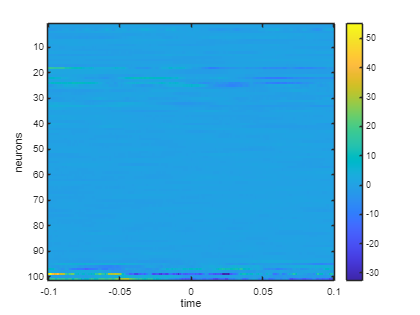


figure, imagesc(sta.time, 1:nNeurons, sta_all), colorbar
xlabel('time')
ylabel('neurons')

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


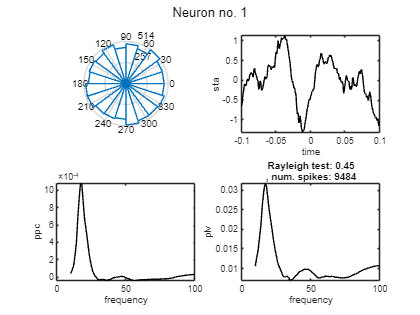

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


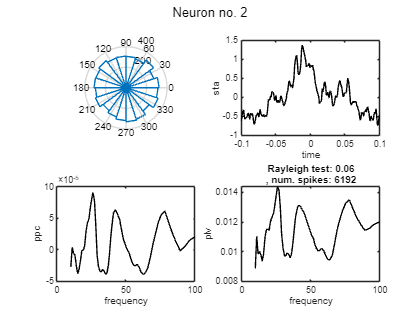

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 3 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds


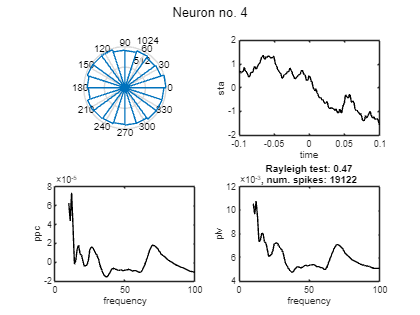

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


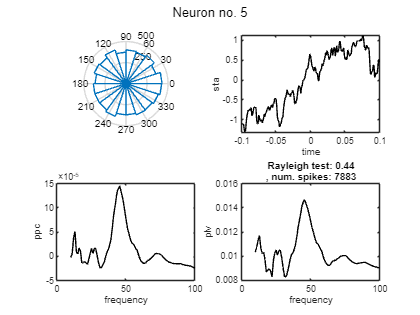

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


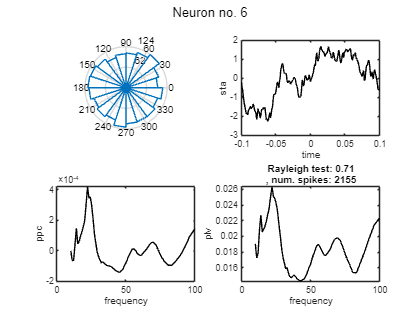

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


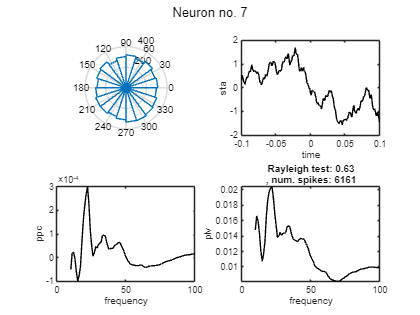

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 3 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds


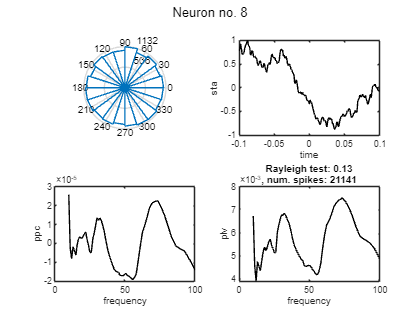

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


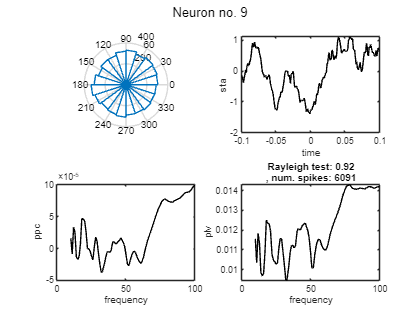

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds


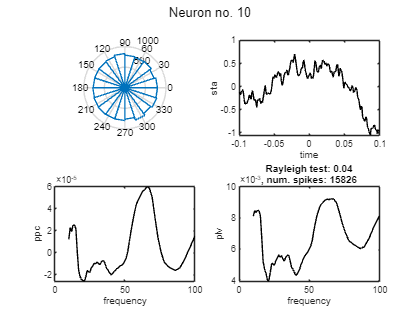

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


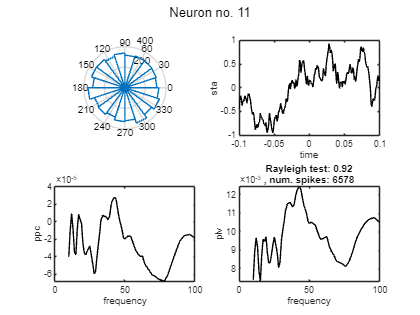

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


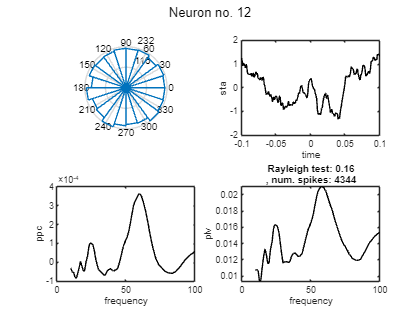

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


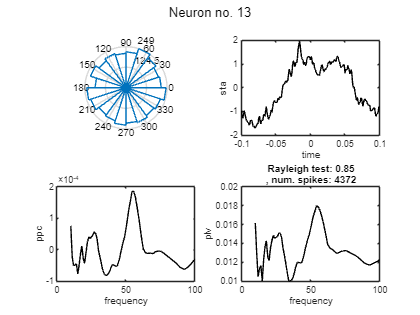

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 3 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 3 seconds


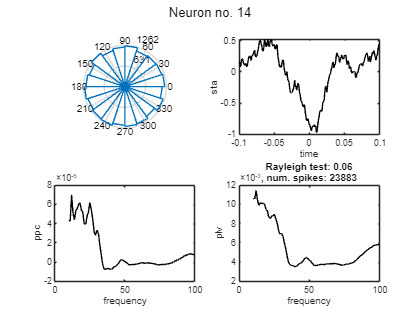

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


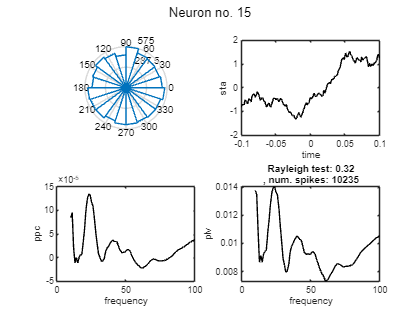

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 7 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 5 seconds


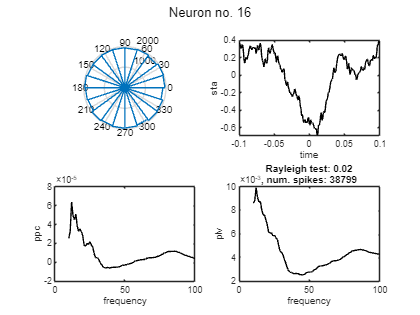

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


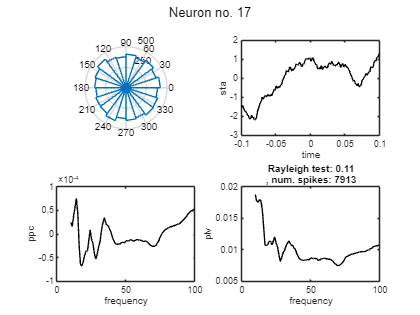

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


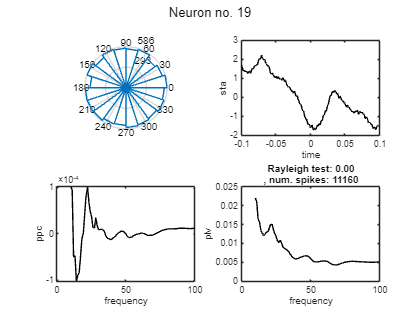

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


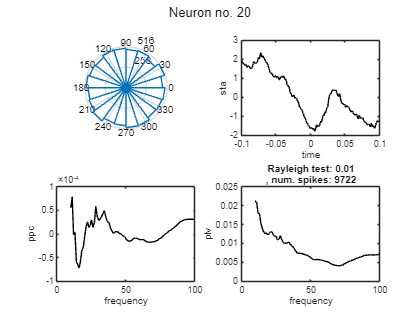

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


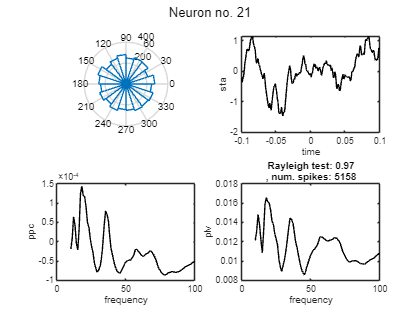

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


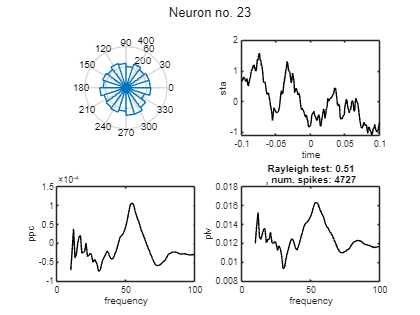

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


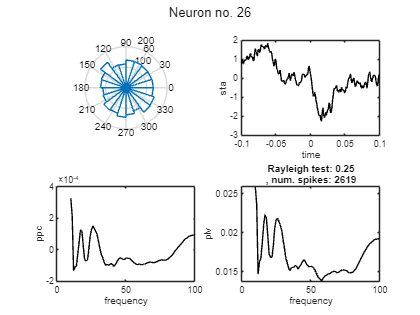

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


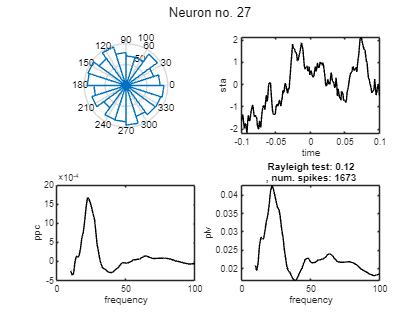

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


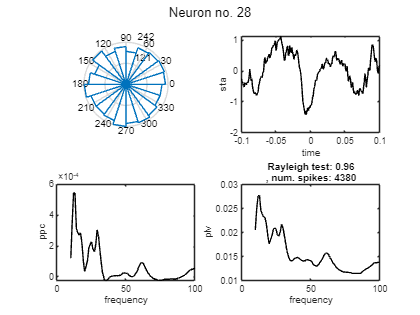

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


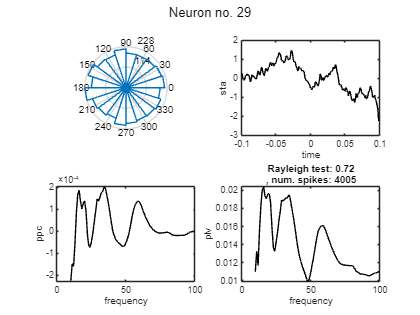

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


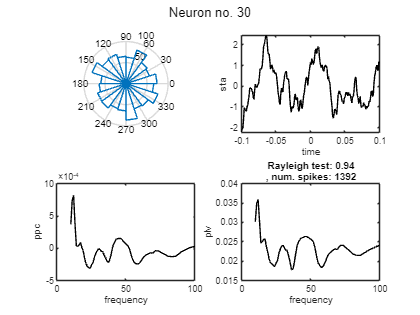

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


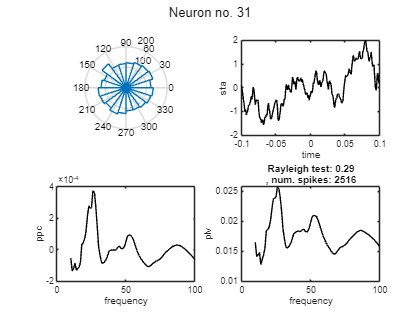

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


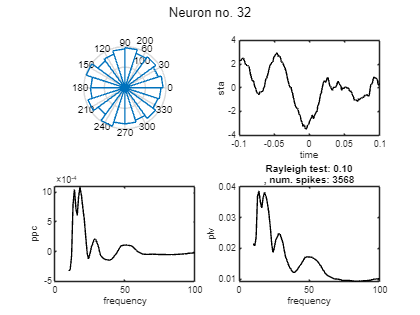

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


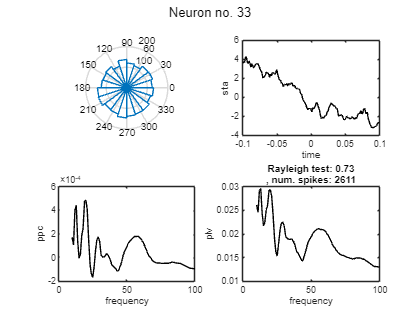

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


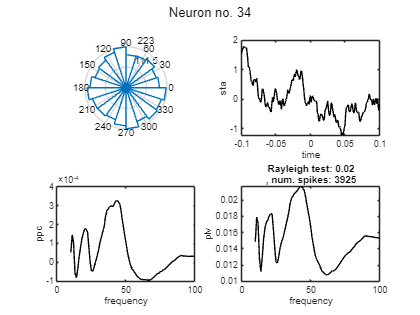

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


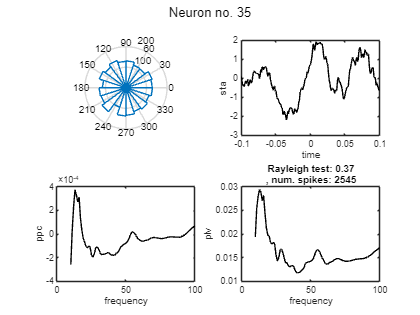

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 26 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 10 seconds


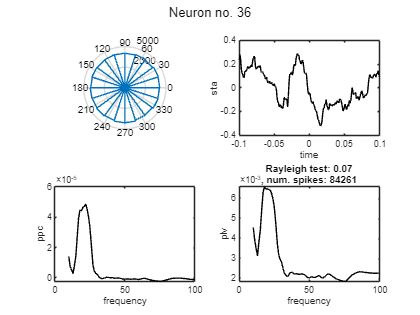

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


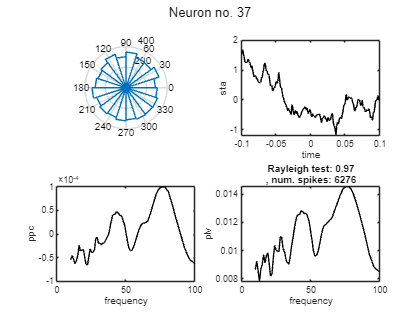

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


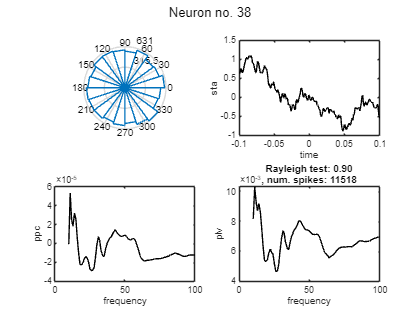

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


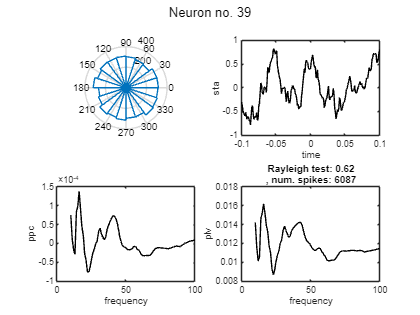

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


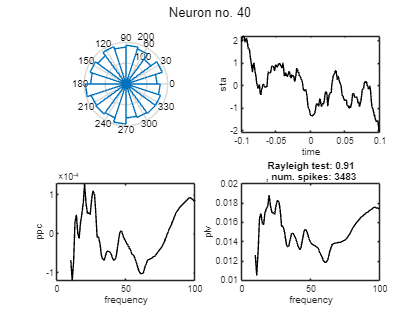

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


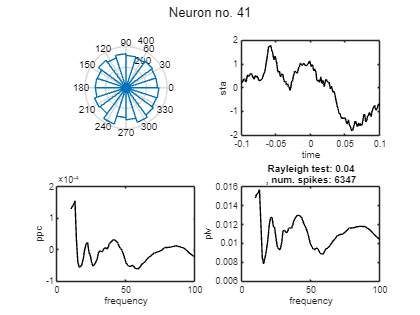

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


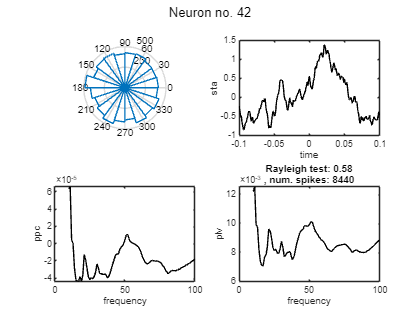

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


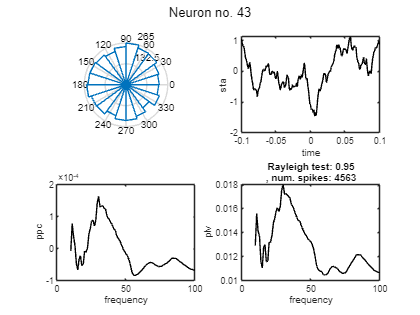

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


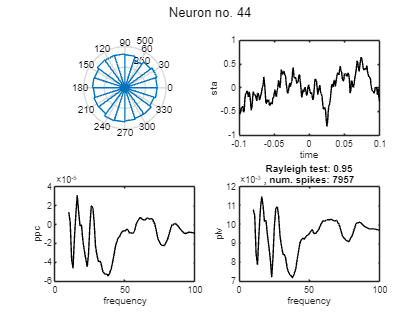

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


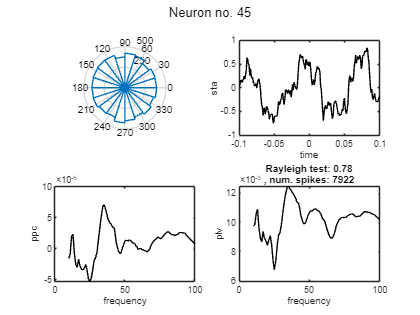

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


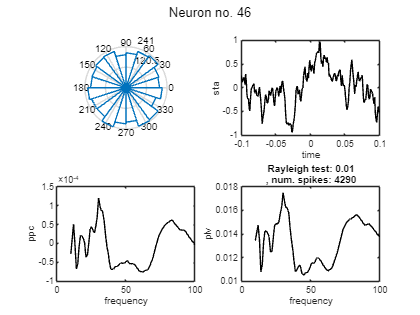

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


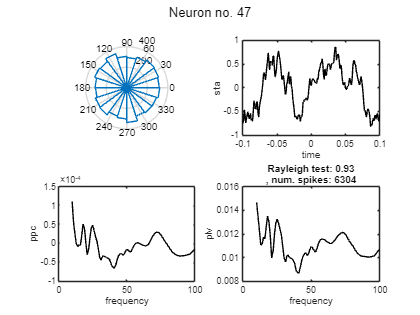

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


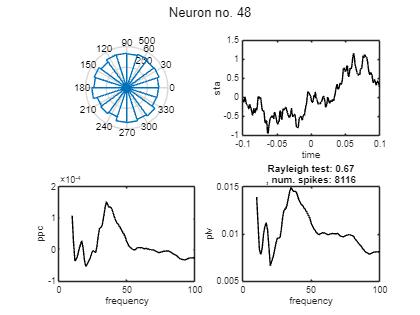

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


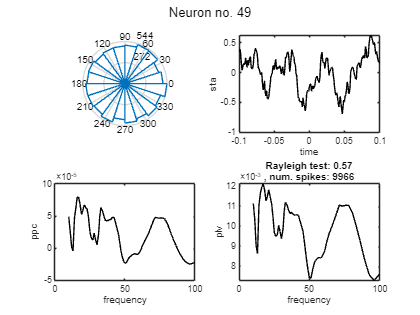

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


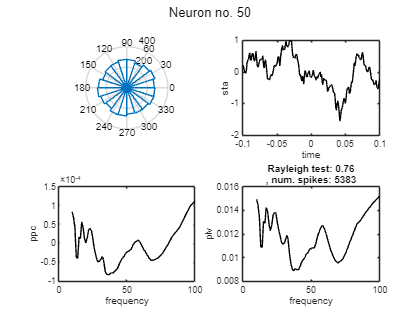

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


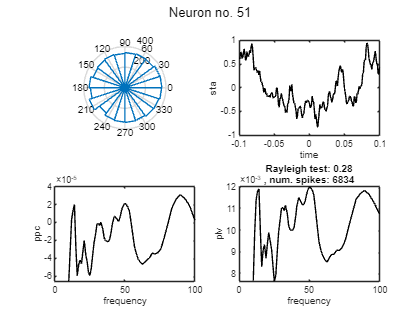

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


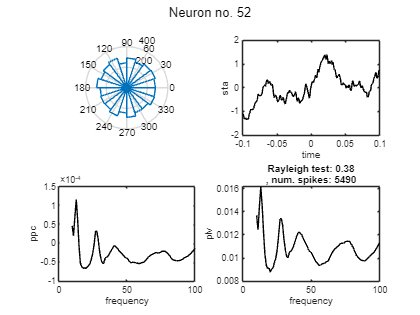

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


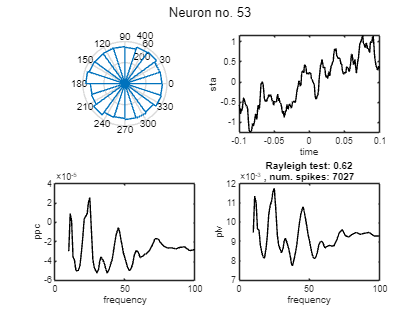

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


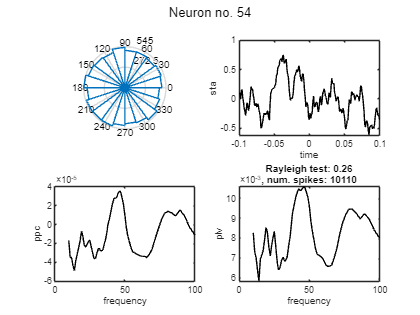

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


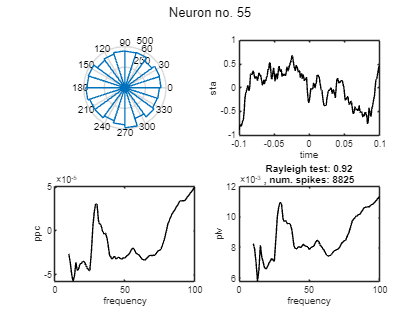

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


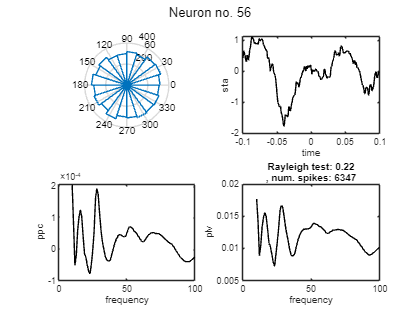

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


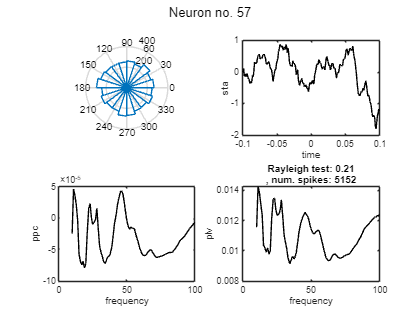

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


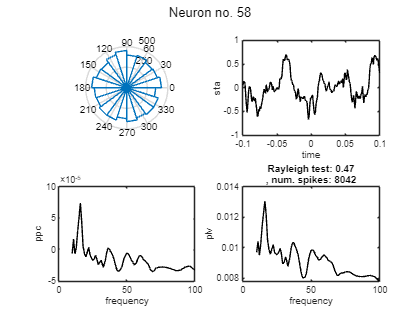

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


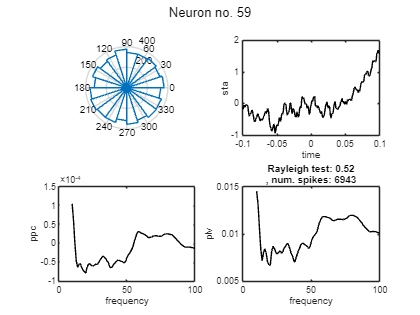

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


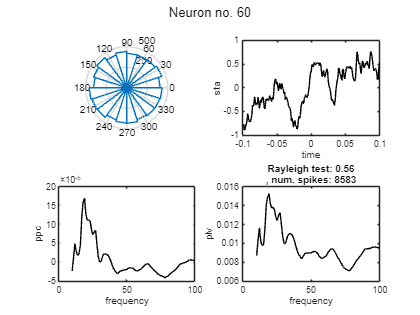

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


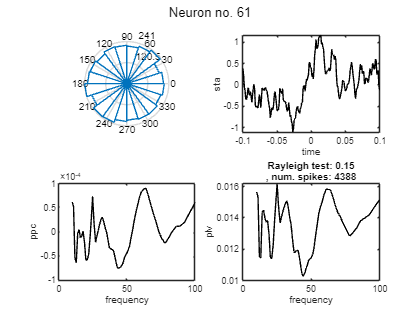

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


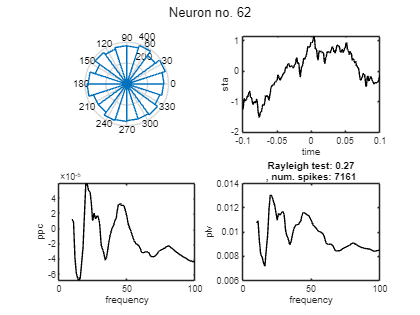

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


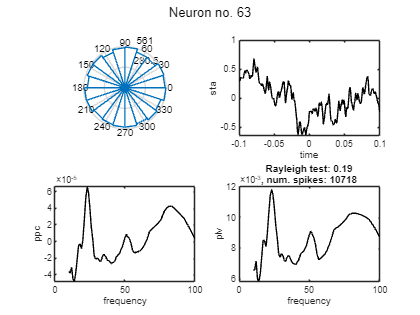

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


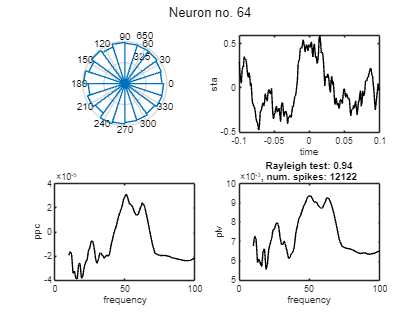

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


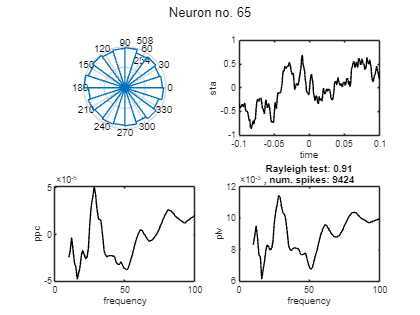

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


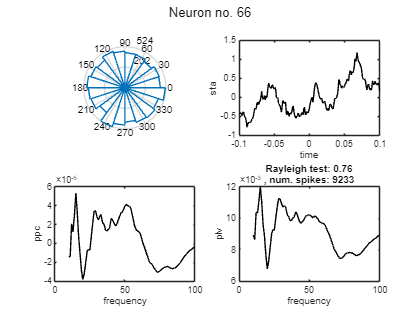

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


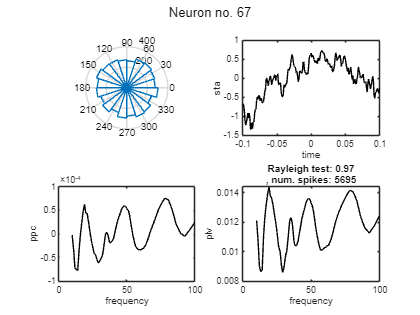

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


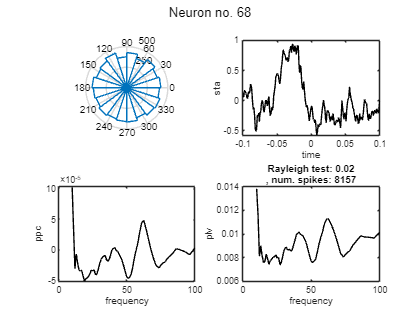

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


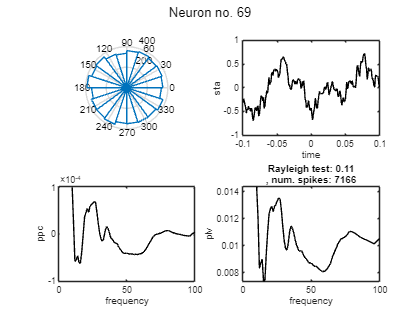

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


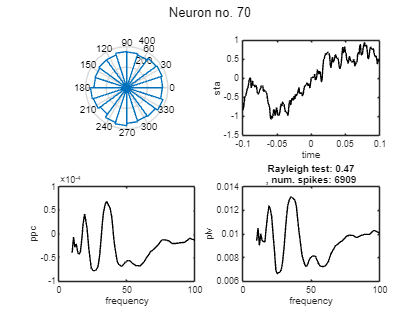

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


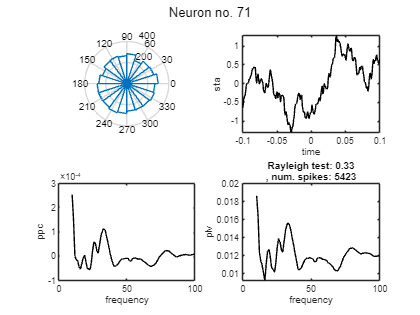

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


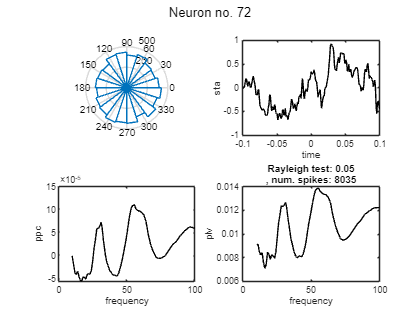

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


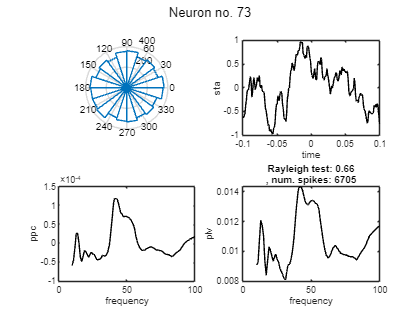

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


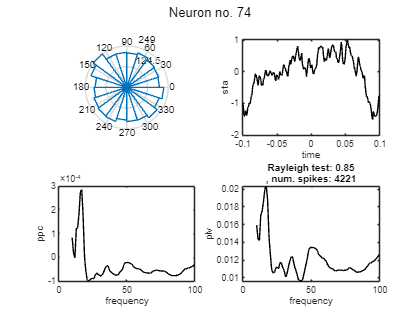

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


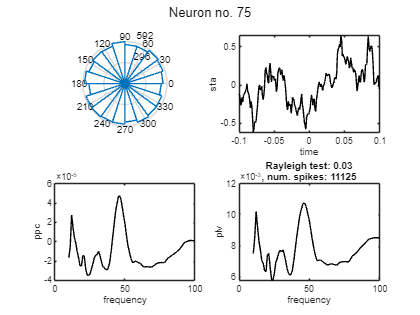

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


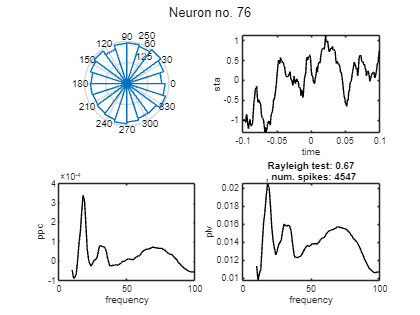

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


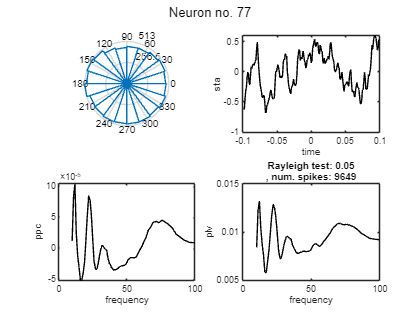

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


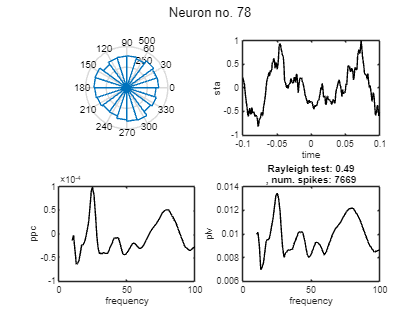

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


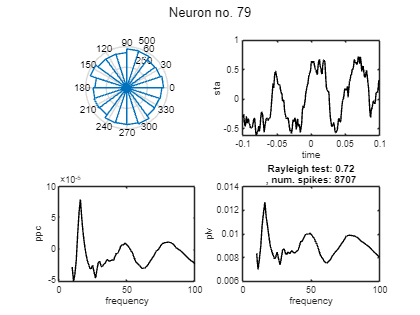

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


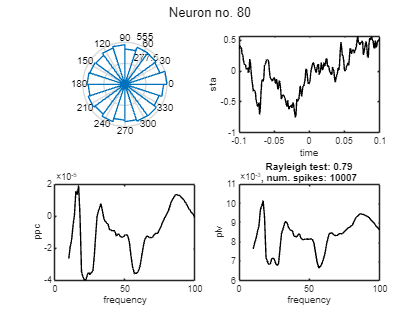

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


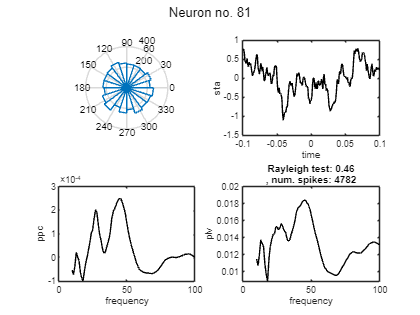

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


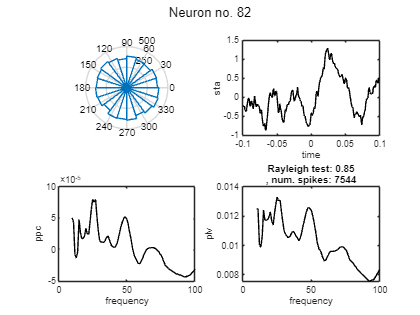

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


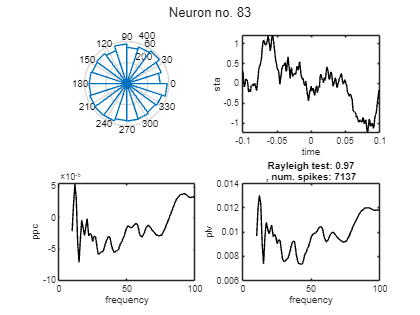

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


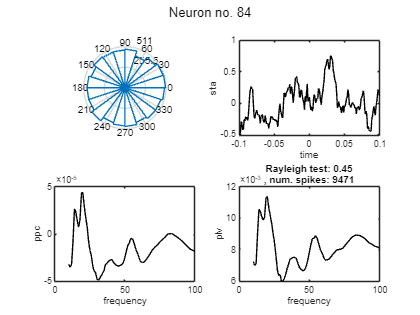

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


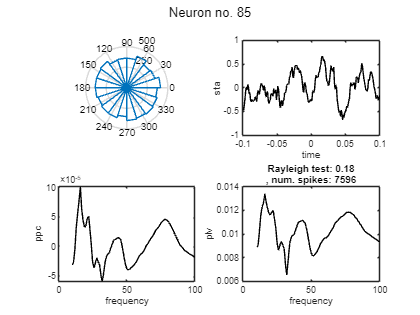

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


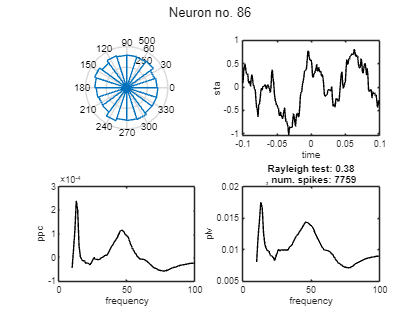

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


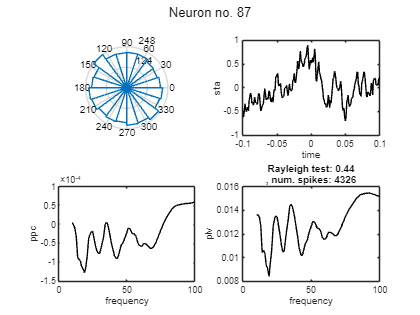

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


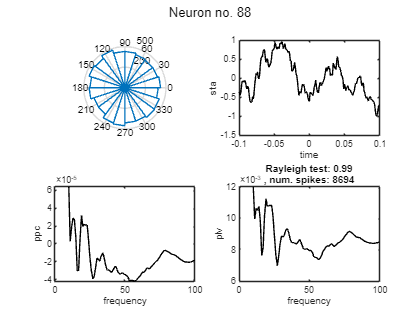

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


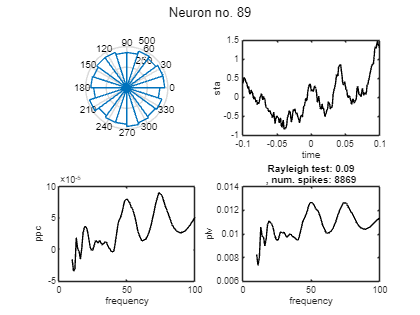

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


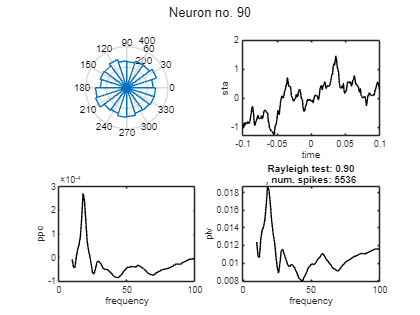

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


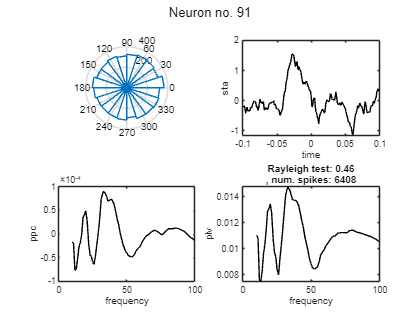

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


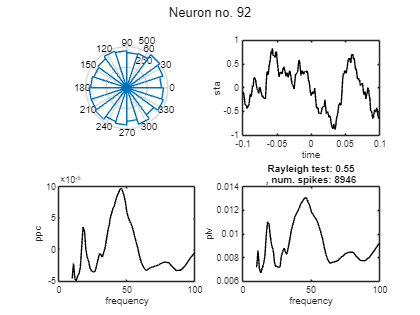

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 2 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


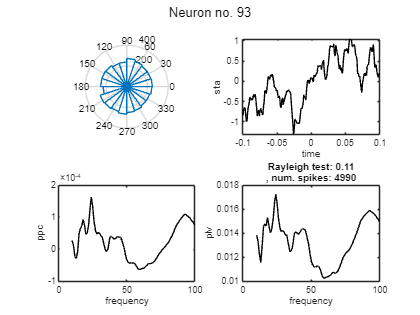

the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 1 seconds


the input is spike data with 101 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


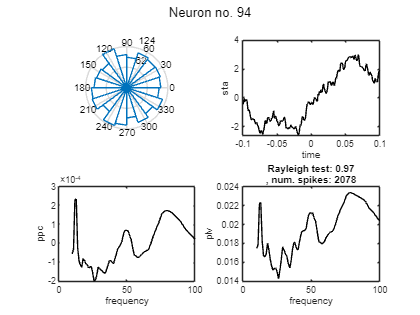

for iNeuron = 1:101

    if length(sts.time{iNeuron})<1000, continue,end

    f_ind = nearest(sts.freq, 40); 
    neuron_ind = iNeuron; 
    
    % compute the rayleigh test
    cfg = []; 
    cfg.spikechannel = neuron_ind; 
    cfg.method = 'ral';      
    stat_ral = ft_spiketriggeredspectrum_stat(cfg, sts); % this function takes only one input at a time
    
    % for illustration also show the plv
    cfg = []; 
    cfg.spikechannel = neuron_ind; 
    cfg.method = 'plv';      
    stat_plv = ft_spiketriggeredspectrum_stat(cfg, sts); % this function takes only one input at a time
           
    %
    figure, 
    subplot(2,2,1)
    % visualize the angles for this neuron
    angles = angle(sts.fourierspctrm{iNeuron}(:,:,f_ind));        
    rose(angles(:, 1),20)        
    
    % visualize the sta
    subplot(2,2,2)
    plot(sta.time, sta_all(iNeuron,:),'k')
    xlabel('time')
    ylabel('sta')

    % visualize the ppc for this neuron
    subplot(2,2,3)
    plot(stat_ppc.freq, ppc_all(iNeuron,:),'k')
    xlabel('frequency')
    ylabel('ppc')
    
    subplot(2,2,4)
    plot(stat_plv.freq, mean(stat_plv.plv, 1),'k')
    xlabel('frequency')
    ylabel('plv')

    title(sprintf("Rayleigh test: %2.2f\n, num. spikes: %d", stat_ral.ral(f_ind),n_spikes(iNeuron,f_ind)))
    sgtitle("Neuron no. " + num2str(iNeuron));
end

## PART 6: COMPUTE GROUP STATISTICS FOR ALL THE NEURONS

## weighted average 

[w_ppc,uw_ppc,thresh_ppc] = compute_avg_ppc(n_spikes,ppc_all);

% plot the results 
figure, 
h(1)=plot(stat_ppc.freq, w_ppc,'g'); 
hold on, 
h(2)=plot(stat_ppc.freq, uw_ppc,'r'); 
hold on, 
h(3)=plot(stat_ppc.freq, thresh_ppc,'b');
legend(h,'weighted', 'unweighted', 'threshold50')

## PART 7: COMPUTE THE SPECTRUM IN A DIFFERENT WAY, TAKING THE FOURIER AROUND EACH SPIKE

cfg = []; 
cfg.timwin= [-0.1 0.1]; 
cfg.foilim = [10 100]; 
cfg.taper = 'hann'; 
cfg.spikechannel = 1:length(spike.trial); 
sts_fft = ft_spiketriggeredspectrum_fft(cfg, lfp, spike); 

% 
nNeurons = length(spike.label); 
ppc_all = NaN(nNeurons, length(sts_fft.freq)); 
n_spikes = NaN(nNeurons, length(sts_fft.freq)); 
for iNeuron = 1:nNeurons

    if length(sts.time{iNeuron})<3, continue,end 
    
    % the code to compute for a single neuron
    cfg = []; 
    cfg.spikechannel = iNeuron; 
    cfg.method = 'ppc1'; 
    stat_ppc = ft_spiketriggeredspectrum_stat(cfg, sts_fft); % this function takes only one input at a time
    
    % collect the data in some array for all neurons
    ppc_all(iNeuron,:) = stat_ppc.ppc1; % collect the ppc values across units
    n_spikes(iNeuron,:) = stat_ppc.nspikes; % collect the number of spikes for each neuron
end

%
[w_ppc,uw_ppc,thresh_ppc] = compute_avg_ppc(n_spikes,ppc_all);

% plot the results 
figure, 
h(1)=plot(stat_ppc.freq, w_ppc,'g'); 
hold on, 
h(2)=plot(stat_ppc.freq, uw_ppc,'r'); 
hold on, 
h(3)=plot(stat_ppc.freq, thresh_ppc,'b');
legend(h,'weighted', 'unweighted', 'threshold50')

## PART 8: COMPUTE THE SPIKE FIELD COHERENCE

cfg = []; 
cfg.method = 'mtmfft'; 
cfg.taper = 'dpss';
cfg.foilim = [1 100];
cfg.tapsmofrq = 8;
cfg.output = 'fourier';
ft = ft_freqanalysis(cfg, data_all);

cfg = []; 
cfg.method = 'coh';
con = ft_connectivityanalysis(cfg, ft); 

coh_spike_lfp = squeeze(con.cohspctrm(1,:,:));
figure, plot(con.freq, nanmean(coh_spike_lfp,1)); 


## 
$$END$$
